# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

### Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex5' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

### 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

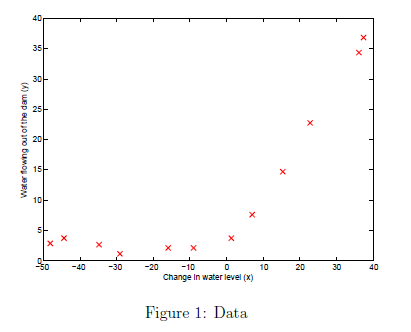

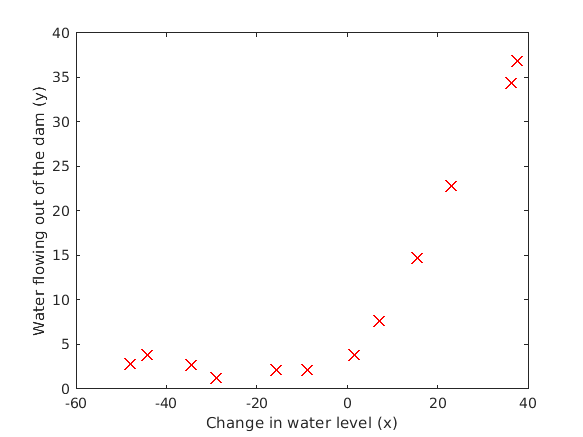

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment

load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');

grad =   -15.3030
  598.2507


ylabel('Water flowing out of the dam (y)');

Cost at theta = [1 ; 1]: 303.993192

### 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overtting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Cost at theta = [1 ; 1]: %f', J);

grad =   -15.3030
  598.2507


Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\textrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\textrm{for}\;\;j=0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

grad =   -11.2176
 -245.6520


grad =   -11.2381
 -242.2045


grad =   -11.2790
 -235.3094


grad =   -11.4018
 -214.6242


grad =   -11.7704
 -152.5687


grad =   -12.6798
    0.5790


Iteration     1 | Cost: 1.052435e+02


grad =   -11.2240
    0.5125


grad =    -8.3124
    0.3796


grad = 	1.0e+-10 *

   -0.0029
    0.4706


Iteration     2 | Cost: 2.237391e+01


grad = 	1.0e+-5 *

    0.0024
   -0.4110


grad = 	1.0e+-6 *

    0.0024
   -0.4110


grad = 	1.0e+-6 *

    0.0022
   -0.3699


grad = 	1.0e+-6 *

    0.0015
   -0.2465


grad = 	1.0e+-6 *

    0.0010
   -0.1643


grad = 	1.0e+-6 *

    0.0009
   -0.1479


grad = 	1.0e+-6 *

    0.0008
   -0.1331


grad = 	1.0e+-7 *

    0.0053
   -0.8871


grad = 	1.0e+-7 *

    0.0047
   -0.7984


grad = 	1.0e+-7 *

    0.0043
   -0.7185


grad = 	1.0e+-7 *

    0.0028
   -0.4788


grad = 	1.0e+-7 *

    0.0019
   -0.3189


grad = 	1.0e+-7 *

    0.0013
   -0.2124


grad = 	1.0e+-7 *

    0.0011
   -0.1911


grad = 	1.0e+-7 *

    0.0010
   -0.1719


grad = 	1.0e+-7 *

    0.0009
   -0.1547


grad = 	1.0e+-7 *

    0.0008
   -0.1392


grad = 	1.0e+-7 *

    0.0007
   -0.1252


grad = 	1.0e+-7 *

    0.0007
   -0.1127


grad = 	1.0e+-7 *

    0.0006
   -0.1013


grad = 	1.0e+-8 *

    0.0054
   -0.9116


grad = 	1.0e+-5 *

   -0.0046
    0.7739


grad = 	1.0e+-6 *

   -0.0046
    0.7739


grad = 	1.0e+-6 *

   -0.0031
    0.5144


grad = 	1.0e+-6 *

   -0.0028
    0.4630


grad = 	1.0e+-6 *

   -0.0025
    0.4167


grad = 	1.0e+-6 *

   -0.0022
    0.3750


grad = 	1.0e+-6 *

   -0.0020
    0.3375


grad = 	1.0e+-6 *

   -0.0018
    0.3038


grad = 	1.0e+-6 *

   -0.0012
    0.2010


grad = 	1.0e+-6 *

   -0.0011
    0.1809


grad = 	1.0e+-6 *

   -0.0010
    0.1628


grad = 	1.0e+-6 *

   -0.0009
    0.1466


grad = 	1.0e+-6 *

   -0.0008
    0.1319


grad = 	1.0e+-6 *

   -0.0007
    0.1187


grad = 	1.0e+-6 *

   -0.0006
    0.1068


grad = 	1.0e+-7 *

   -0.0042
    0.6970


grad = 	1.0e+-7 *

   -0.0038
    0.6273


grad = 	1.0e+-7 *

   -0.0034
    0.5647


grad = 	1.0e+-7 *

   -0.0030
    0.5082


grad = 	1.0e+-7 *

   -0.0027
    0.4575


grad = 2×1
   -0.0025
    0.4118


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

    Finally, the code below should also plot the best fit line, resulting in an image similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

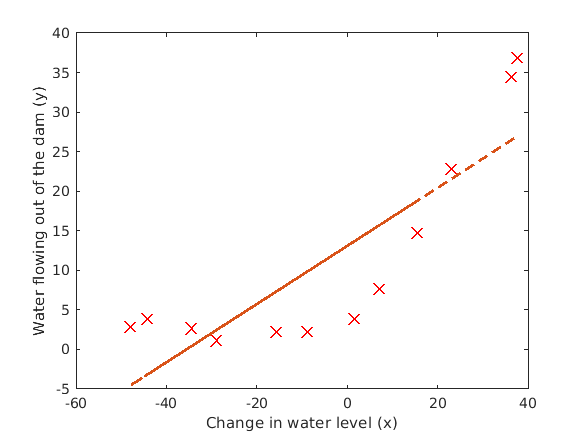

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');

ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

grad =    -2.1343
   34.0140


grad =    -1.6662
   26.5535


grad =    -0.7299
   11.6325


Iteration     1 | Cost: 2.663868e-01


grad =     3.3766
  -53.8125


grad = 	1.0e+-13 *

   -0.0089
    0.1415


Iteration     2 | Cost: 3.944305e-31


grad = 	1.0e+-11 *

    0.0170
   -0.2704


grad = 	1.0e+-12 *

    0.0164
   -0.2619


grad = 	1.0e+-13 *

    0.0089
   -0.1415


grad =      0
     0


Iteration     3 | Cost: 0.000000e+00


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad = 2×1
     0
     0


grad = 2×1
     0
     0


grad = 2×1
  -12.3370
 -367.6732


grad = 2×1
   -1.6538
   34.1090


grad = 2×1
   -0.9935
   17.9472


grad = 2×1
   -0.2598
   -0.0126


Iteration     1 | Cost: 4.282328e-01


grad = 2×1
   -0.2561
   -0.0124


grad = 2×1
   -0.2487
   -0.0121


grad = 2×1
   -0.2264
   -0.0110


grad = 2×1
   -0.1596
   -0.0077


grad = 2×1
    0.0377
   -0.9537


Iteration     2 | Cost: 8.332343e-30


grad = 2×1
   -0.0273
    0.6675


grad = 2×1
   -0.0273
    0.6675


grad = 2×1
   -0.0273
    0.6674


grad = 2×1
   -0.0272
    0.6665


grad = 2×1
   -0.0269
    0.6580


grad = 2×1
   -0.0233
    0.5711


grad = 2×1
         0
   -0.2935


Iteration     3 | Cost: 9.860761e-32


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
   -0.0222
    0.3539


grad = 2×1
    0.0080
   -0.1958


grad = 2×1
    0.0082
   -0.2014


grad = 2×1
    0.0111
   -0.2943


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
    0.0044
   -0.1295


grad = 2×1
         0
   -0.2935


grad = 2×1
   -9.9193
 -197.7035


grad = 2×1
  -12.5556
 -391.7409


grad = 2×1
  -12.5630
 -389.6896


grad = 2×1
  -12.5780
 -385.5869


grad = 2×1
  -12.6229
 -373.2788


grad = 2×1
  -12.7576
 -336.3547


grad = 2×1
  -13.1617
 -225.5823


grad = 2×1
  -13.9863
    0.4483


Iteration     1 | Cost: 1.021540e+02


grad = 2×1
  -12.2625
    0.3930


grad = 2×1
   -8.8149
    0.2825


grad = 2×1
   -0.0006
    0.1643


Iteration     2 | Cost: 3.286595e+00


grad = 2×1
    0.0005
   -0.1335


grad = 2×1
    0.0005
   -0.1334


grad = 2×1
    0.0004
   -0.1201


grad = 2×1
    0.0004
   -0.1199


grad = 2×1
    0.0004
   -0.1079


grad = 2×1
    0.0026
   -0.7188


grad = 2×1
    0.0024
   -0.6467


grad = 2×1
    0.0016
   -0.4303


grad = 2×1
    0.0014
   -0.3871


grad = 2×1
    0.0013
   -0.3483


grad = 2×1
    0.0011
   -0.3133


grad = 2×1
    0.0010
   -0.2818


grad = 2×1
    0.0009
   -0.2534


grad = 2×1
    0.0009
   -0.2387


grad = 2×1
    0.0008
   -0.2132


grad = 2×1
    0.0007
   -0.1902


grad = 2×1
    0.0006
   -0.1696


grad = 2×1
    0.0006
   -0.1510


grad = 2×1
    0.0005
   -0.1343


grad = 2×1
    0.0004
   -0.1192


grad = 2×1
    0.0004
   -0.1056


grad = 2×1
   -0.0031
    0.8495


grad = 2×1
   -0.0028
    0.7646


grad = 2×1
   -0.0025
    0.6881


grad = 2×1
   -0.0023
    0.6193


grad = 2×1
   -0.0023
    0.6208


grad = 2×1
   -0.0021
    0.5589


grad = 2×1
   -0.0019
    0.5032


grad = 2×1
   -0.0019
    0.5181


grad = 2×1
   -0.0017
    0.4679


grad = 2×1
   -0.0016
    0.4227


grad = 2×1
   -0.0021
    0.5715


grad = 2×1
   -0.0019
    0.5317


grad = 2×1
   -0.0018
    0.4945


grad = 2×1
   -0.0007
    0.1985


Iteration     4 | Cost: 3.286595e+00


grad = 2×1
   -0.0006
    0.2335


Iteration     5 | Cost: 3.286595e+00


grad = 2×1
    0.0008
   -0.2194


grad = 2×1
    0.0021
   -0.1540


grad = 2×1
   -0.0005
    0.2030


grad = 2×1
    0.0001
    0.1026


Iteration     6 | Cost: 3.286595e+00


grad = 2×1
    0.0010
   -0.2080


grad = 2×1
    0.0009
    0.7390


grad = 2×1
    0.0001
    0.1026


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
    0.0003
    0.8953


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0003
    0.8953


grad = 2×1
    0.0027
   -0.7193


grad = 2×1
    0.0018
   -0.4791


grad = 2×1
    0.0018
   -0.4696


grad = 2×1
    0.0018
   -0.3704


grad = 2×1
   -0.0003
    0.4761


grad = 2×1
    0.0001
    0.1026


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
    0.0001
    0.1026


grad = 2×1
    0.0003
    0.8953


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
   -0.0009
    0.7816


grad = 2×1
    0.0001
    0.1026


grad = 2×1
   -1.0197
  172.4830


grad = 2×1
  -18.6262
 -639.0896


grad = 2×1
  -18.6149
 -637.5965


grad = 2×1
  -18.5925
 -634.6104


grad = 2×1
  -18.5252
 -625.6520


grad = 2×1
  -18.3232
 -598.7768


grad = 2×1
  -17.7173
 -518.1514


grad = 2×1
  -15.8995
 -276.2751


Iteration     1 | Cost: 1.438726e+02


grad = 2×1
   -9.5636
  559.5656


grad = 2×1
  -13.7954
    1.3080


Iteration     2 | Cost: 1.035224e+02


grad = 2×1
  -11.7967
 -157.2596


Iteration     3 | Cost: 7.536716e+01


grad = 2×1
   -8.3702
  -55.1758


grad = 2×1
   -3.1045
  101.7042


Iteration     4 | Cost: 1.615422e+01


grad = 2×1
   15.2680
 -214.7555


grad = 2×1
    0.7849
   34.7119


Iteration     5 | Cost: 3.619255e+00


grad = 2×1
  -11.8838
 -525.5837


grad = 2×1
   -0.4820
  -21.3176


grad = 2×1
   -0.0854
   -3.7767


Iteration     6 | Cost: 2.851871e+00


grad = 2×1
    3.1827
  431.4575


grad = 2×1
    0.2414
   39.7467


grad = 2×1
   -0.0527
    0.5756


Iteration     7 | Cost: 2.844569e+00


grad = 2×1
   -0.2621
  -27.7319


grad = 2×1
   -0.0736
   -2.2551


grad = 2×1
   -0.0570
   -0.0052


Iteration     8 | Cost: 2.844392e+00


grad = 2×1
   -0.0512
   -0.0047


grad = 2×1
   -0.0397
   -0.0036


grad = 2×1
   -0.0052
   -0.0005


Iteration     9 | Cost: 2.842692e+00


grad = 2×1
    0.3797
   46.3233


grad = 2×1
    0.0333
    4.6319


grad = 2×1
   -0.0013
    0.4628


grad = 2×1
   -0.0048
    0.0459


grad = 2×1
   -0.0051
    0.0043


Iteration    10 | Cost: 2.842692e+00


grad = 2×1
   -0.0051
    0.0023


grad = 2×1
   -0.0051
   -0.0016


Iteration    11 | Cost: 2.842692e+00


grad = 2×1
   -0.0051
    0.0000


grad = 2×1
   -0.0051
    0.0032


grad = 2×1
   -0.0049
    0.0129


grad = 2×1
   -0.0045
    0.0379


Iteration    12 | Cost: 2.842691e+00


grad = 2×1
   -0.0041
    0.0419


grad = 2×1
   -0.0033
    0.0498


grad = 2×1
   -0.0009
    0.0735


Iteration    13 | Cost: 2.842682e+00


grad = 2×1
   -0.0007
   -0.0988


grad = 2×1
   -0.0008
   -0.0069


Iteration    14 | Cost: 2.842678e+00


grad = 2×1
    0.0064
   -0.0066


grad = 2×1
   -0.0001
   -0.0068


Iteration    15 | Cost: 2.842678e+00


grad = 2×1
    0.0006
    0.0836


grad = 2×1
    0.0000
    0.0022


Iteration    16 | Cost: 2.842678e+00


grad = 2×1
   -0.0002
   -0.0260


grad = 2×1
   -0.0048
   -0.6282


Iteration    17 | Cost: 2.842678e+00


grad = 2×1
    0.0001
    0.0092


grad = 2×1
    0.0026
    0.3579


grad = 2×1
   -0.1161
    0.0047


Iteration    18 | Cost: 2.842678e+00


grad = 2×1
   -0.1046
    0.0046


grad = 2×1
   -0.1131
    0.0046


grad = 2×1
   -0.1158
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.1161
    0.0047


grad = 2×1
   -0.0033
   -0.3619


grad = 2×1
   -0.0081
   -0.1526


Iteration    20 | Cost: 2.842678e+00


grad = 2×1
   -0.0284
    0.2102


Iteration    21 | Cost: 2.842678e+00


grad = 2×1
    0.0099
   -0.3463


grad = 2×1
   -0.0079
   -0.3797


Iteration    22 | Cost: 2.842678e+00


grad = 2×1
    0.1557
   -0.2801


grad = 2×1
    0.0084
   -0.3698


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0061
   -0.3786


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
   -0.0063
   -0.3787


grad = 2×1
    0.0027
    0.3613


grad = 2×1
    0.0026
    0.3579


grad = 2×1
    0.0019
    0.3237


grad = 2×1
   -0.0522
   -0.1807


Iteration    24 | Cost: 2.842678e+00


grad = 2×1
   -0.0412
    0.6680


grad = 2×1
   -0.0469
    0.2311


grad = 2×1
   -0.0517
   -0.1395


grad = 2×1
   -0.4928
    0.4581


grad = 2×1
   -0.0514
   -0.1210


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0516
   -0.1293


grad = 2×1
   -0.0517
   -0.1368


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
   -0.0517
   -0.1376


grad = 2×1
    0.0010
    0.1316


grad = 2×1
    0.0005
    0.1300


grad = 2×1
   -0.0042
    0.1137


grad = 2×1
   -0.0456
    0.6662


grad = 2×1
   -0.5156
   -0.9599


grad = 2×1
   -0.0486
    0.2851


grad = 2×1
   -0.0489
    0.2470


grad = 2×1
   -0.5129
   -0.6169


grad = 2×1
   -0.5153
   -0.9256


grad = 2×1
   -0.5155
   -0.9565


grad = 2×1
   -0.5156
   -0.9595


grad = 2×1
   -0.5156
   -0.9599


grad = 2×1
   -0.5156
   -0.9599


grad = 2×1
   -0.5156
   -0.9599


grad = 2×1
   -0.5156
   -0.9599


grad = 2×1
   -0.5156
   -0.9599


grad = 2×1
   -0.5156
   -0.9599


grad = 2×1
   -0.5156
   -0.9599


grad = 2×1
   -0.5156
   -0.9599


grad = 2×1
   -0.5156
   -0.9599


grad = 2×1
   -0.5156
   -0.9599


grad = 2×1
   -0.0522
   -0.1807


grad = 2×1
   -0.6376
  188.9972


grad = 2×1
  -15.4627
 -484.2725


grad = 2×1
  -15.4707
 -481.7442


grad = 2×1
  -15.4866
 -476.6876


grad = 2×1
  -15.5344
 -461.5176


grad = 2×1
  -15.6778
 -416.0078


grad = 2×1
  -16.1079
 -279.4784


grad = 2×1
  -16.9901
    0.5425


Iteration     1 | Cost: 1.592641e+02


grad = 2×1
  -15.6179
    0.4987


grad = 2×1
  -12.8733
    0.4110


grad = 2×1
   -4.6396
    0.1481


Iteration     2 | Cost: 2.404966e+01


grad = 2×1
    0.0633
   -7.2034


grad = 2×1
    2.1521
 -720.2100


grad = 2×1
   -3.9604
  -71.8877


grad = 2×1
   -4.3146
  -34.3255


Iteration     3 | Cost: 2.354137e+01


grad = 2×1
   -4.3368
   -7.8988


Iteration     4 | Cost: 2.281160e+01


grad = 2×1
   -4.6675
  113.1052


grad = 2×1
   -4.3699
    4.2016


Iteration     5 | Cost: 2.276969e+01


grad = 2×1
   -4.3547
    7.4976


grad = 2×1
   -4.3244
   14.0896


grad = 2×1
   -4.2336
   33.8656


Iteration     6 | Cost: 2.224060e+01


grad = 2×1
   -4.0560
   21.8261


grad = 2×1
   -3.7008
   -2.2531


grad = 2×1
   -3.0554
  -45.9992


Iteration     7 | Cost: 1.920606e+01


grad = 2×1
   -1.3156
  -37.0210


Iteration     8 | Cost: 1.475292e+01


grad = 2×1
   -2.5074
  187.0033


grad = 2×1
   -1.4912
   -4.0016


Iteration     9 | Cost: 1.430565e+01


grad = 2×1
   -1.0569
   24.7736


Iteration    10 | Cost: 1.388881e+01


grad = 2×1
   -0.3565
   13.0005


Iteration    11 | Cost: 1.327330e+01


grad = 2×1
   -0.8160
  -95.5466


grad = 2×1
   -0.4025
    2.1458


Iteration    12 | Cost: 1.323519e+01


grad = 2×1
   -0.1896
   -6.5751


Iteration    13 | Cost: 1.319411e+01


grad = 2×1
    0.2505
   -7.2955


grad = 2×1
    0.0128
   -6.9064


Iteration    14 | Cost: 1.317355e+01


grad = 2×1
   -0.0023
    0.3811


Iteration    15 | Cost: 1.315411e+01


grad = 2×1
    0.1259
  -39.9048


grad = 2×1
    0.0105
   -3.6475


grad = 2×1
   -0.0010
   -0.0218


Iteration    16 | Cost: 1.315405e+01


grad = 2×1
   -0.0082
    2.2791


grad = 2×1
   -0.0017
    0.2083


grad = 2×1
   -0.0011
    0.0012


Iteration    17 | Cost: 1.315405e+01


grad = 2×1
   -0.0010
    0.0084


Iteration    18 | Cost: 1.315405e+01


grad = 2×1
   -0.0009
   -0.0013


Iteration    19 | Cost: 1.315405e+01


grad = 2×1
   -0.8387
    0.8750


grad = 2×1
   -0.0007
    0.0051


grad = 2×1
   -0.0003
    0.0138


Iteration    20 | Cost: 1.315405e+01


grad = 2×1
    0.0014
   -0.0118


grad = 2×1
    0.0001
    0.0082


Iteration    21 | Cost: 1.315405e+01


grad = 2×1
   -0.0001
   -0.0098


grad = 2×1
   -0.0616
    0.9950


Iteration    22 | Cost: 1.315405e+01


grad = 2×1
    0.0129
   -0.1964


grad = 2×1
    0.0083
   -0.1259


grad = 2×1
    0.0276
   -0.3638


Iteration    23 | Cost: 1.315405e+01


grad = 2×1
   -0.0004
    0.2014


grad = 2×1
    0.0021
    0.1687


grad = 2×1
    0.0270
   -0.1588


Iteration    24 | Cost: 1.315405e+01


grad = 2×1
    0.0254
    0.2920


grad = 2×1
    0.0256
    0.2470


grad = 2×1
    0.0257
    0.2064


grad = 2×1
    0.0268
   -0.1223


grad = 2×1
    0.2628
    0.4209


Iteration    25 | Cost: 1.315405e+01


grad = 2×1
    0.0270
   -0.3418


grad = 2×1
    0.2635
    0.0376


grad = 2×1
    0.2629
    0.3819


grad = 2×1
    0.2628
    0.4172


grad = 2×1
    0.2628
    0.4202


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.2628
    0.4209


grad = 2×1
    0.0016
   -0.5145


grad = 2×1
    0.0040
   -0.5107


grad = 2×1
    0.0277
   -0.4729


grad = 2×1
    0.2642
   -0.0946


Iteration    27 | Cost: 1.315405e+01


grad = 2×1
    0.2632
   -0.0528


grad = 2×1
    0.2641
   -0.0897


grad = 2×1
    0.2642
   -0.0941


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
    0.2642
   -0.0951


grad = 2×1
   -0.0004
    0.1175


grad = 2×1
    0.0020
    0.1166


grad = 2×1
    0.0258
    0.1082


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2607
    0.5519


grad = 2×1
    0.2633
    0.0754


grad = 2×1
    0.2635
    0.0283


grad = 2×1
    0.2636
    0.0237


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2636
    0.0232


grad = 2×1
    0.2642
   -0.0946


grad = 2×1
    2.4151
   79.9229


grad = 2×1
  -13.2391
 -400.3995


grad = 2×1
  -13.2508
 -397.8183


grad = 2×1
  -13.2743
 -392.6559


grad = 2×1
  -13.3447
 -377.1687


grad = 2×1
  -13.5558
 -330.7071


grad = 2×1
  -14.1892
 -191.3223


Iteration     1 | Cost: 1.531141e+02


grad = 2×1
  -16.1263
  242.7120


grad = 2×1
  -15.0511
    1.7902


Iteration     2 | Cost: 1.350947e+02


grad = 2×1
  -12.0065
 -155.2224


Iteration     3 | Cost: 1.137334e+02


grad = 2×1
  -10.3357
  -86.8539


grad = 2×1
   -6.9942
   49.8831


Iteration     4 | Cost: 4.404199e+01


grad = 2×1
    7.4075
 -464.3988


grad = 2×1
   -3.1398
  -87.7551


Iteration     5 | Cost: 2.957435e+01


grad = 2×1
    9.6593
 -259.3547


grad = 2×1
   -1.0354
 -115.9691


Iteration     6 | Cost: 2.719561e+01


grad = 2×1
   -0.7177
  -80.3819


grad = 2×1
   -0.0822
   -9.2074


Iteration     7 | Cost: 1.949283e+01


grad = 2×1
  -11.6668
  221.4645


grad = 2×1
   -1.2407
   13.8598


grad = 2×1
   -0.1981
   -6.9007


grad = 2×1
   -0.1324
   -8.2072


Iteration     8 | Cost: 1.949128e+01


grad = 2×1
   -0.1337
   -7.8265


grad = 2×1
   -0.1363
   -7.0651


grad = 2×1
   -0.1441
   -4.7808


grad = 2×1
   -0.1610
    0.1989


Iteration     9 | Cost: 1.945708e+01


grad = 2×1
   -0.1202
    0.1485


grad = 2×1
   -0.0386
    0.0477


Iteration    10 | Cost: 1.944472e+01


grad = 2×1
    0.0042
   -1.0912


grad = 2×1
    0.3833
 -109.0723


grad = 2×1
    0.0036
  -10.8643


grad = 2×1
   -0.0344
   -1.0435


grad = 2×1
   -0.0382
   -0.0614


grad = 2×1
   -0.0386
    0.0288


Iteration    11 | Cost: 1.944472e+01


grad = 2×1
   -0.0385
    0.0254


grad = 2×1
   -0.0385
    0.0186


grad = 2×1
   -0.0384
   -0.0018


grad = 2×1
   -0.0380
   -0.0631


Iteration    12 | Cost: 1.944471e+01


grad = 2×1
   -0.0378
   -0.0505


grad = 2×1
   -0.0375
   -0.0254


grad = 2×1
   -0.0365
    0.0500


grad = 2×1
   -0.0336
    0.2760


Iteration    13 | Cost: 1.944453e+01


grad = 2×1
   -0.0270
   -0.0221


grad = 2×1
   -0.0190
   -0.3846


Iteration    14 | Cost: 1.944425e+01


grad = 2×1
    0.0134
   -0.6615


grad = 2×1
   -0.0020
   -0.5298


Iteration    15 | Cost: 1.944411e+01


grad = 2×1
    0.0000
    0.0022


Iteration    16 | Cost: 1.944396e+01


grad = 2×1
    0.0011
   -0.2394


grad = 2×1
    0.0001
   -0.0219


grad = 2×1
    0.0197
   -0.1776


Iteration    17 | Cost: 1.944396e+01


grad = 2×1
   -0.0001
    0.0190


grad = 2×1
    0.0000
    0.0017


grad = 2×1
    0.1879
    0.1419


Iteration    18 | Cost: 1.944396e+01


grad = 2×1
    0.0166
    0.1020


grad = 2×1
    0.0122
    0.2776


Iteration    19 | Cost: 1.944396e+01


grad = 2×1
    0.0977
    0.7742


Iteration    20 | Cost: 1.944396e+01


grad = 2×1
    0.0000
   -0.0012


grad = 2×1
    0.1035
   -0.5396


grad = 2×1
    0.1012
   -0.0133


Iteration    21 | Cost: 1.944396e+01


grad = 2×1
    0.9539
   -0.1304


grad = 2×1
    0.8380
   -0.1259


grad = 2×1
    0.4903
   -0.1126


Iteration    22 | Cost: 1.944396e+01


grad = 2×1
   -0.0000
    0.0050


grad = 2×1
    0.0016
    0.4984


grad = 2×1
    0.0458
    0.4883


grad = 2×1
    0.4831
    0.9986


Iteration    23 | Cost: 1.944396e+01


grad = 2×1
    0.4839
    0.5004


grad = 2×1
    0.4856
   -0.4961


Iteration    24 | Cost: 1.944396e+01


grad = 2×1
    0.4749
    0.4642


grad = 2×1
    0.0455
    0.2214


Iteration    25 | Cost: 1.944396e+01


grad = 2×1
    0.0431
    0.2584


grad = 2×1
    0.0381
    0.3325


grad = 2×1
    0.0233
    0.5548


Iteration    26 | Cost: 1.944396e+01


grad = 2×1
    0.0143
   -0.4724


Iteration    27 | Cost: 1.944396e+01


grad = 2×1
   -0.0001
   -0.0034


grad = 2×1
   -0.0101
   -0.3811


grad = 2×1
    0.0028
   -0.8063


grad = 2×1
    0.0131
   -0.5058


grad = 2×1
    0.0140
   -0.4810


grad = 2×1
    0.0142
   -0.4738


grad = 2×1
    0.0143
   -0.4726


grad = 2×1
    0.0142
   -0.4732


grad = 2×1
    0.0142
   -0.4735


grad = 2×1
    0.0142
   -0.4737


grad = 2×1
    0.0142
   -0.4738


grad = 2×1
    0.0142
   -0.4737


grad = 2×1
    0.0142
   -0.4737


grad = 2×1
    0.0142
   -0.4737


grad = 2×1
    0.0142
   -0.4737


grad = 2×1
    0.0142
   -0.4738


grad = 2×1
    0.0142
   -0.4738


grad = 2×1
    0.0142
   -0.4738


grad = 2×1
    0.0142
   -0.4738


grad = 2×1
    0.0142
   -0.4738


grad = 2×1
    0.0142
   -0.4738


grad = 2×1
   -0.0002
    0.0490


grad = 2×1
   -0.0000
    0.0049


grad = 2×1
   -0.0008
    0.4431


grad = 2×1
    0.1202
    0.1789


Iteration    29 | Cost: 1.944396e+01


grad = 2×1
    0.1047
    0.8619


grad = 2×1
    0.0074
    0.2228


Iteration    30 | Cost: 1.944396e+01


grad = 2×1
    0.0696
    0.7209


Iteration    31 | Cost: 1.944396e+01


grad = 2×1
    0.0031
   -0.2034


grad = 2×1
    0.0093
   -0.1385


grad = 2×1
    0.0719
    0.5103


Iteration    32 | Cost: 1.944396e+01


grad = 2×1
    0.0722
    0.4396


grad = 2×1
    0.0726
    0.2981


grad = 2×1
    0.0729
    0.2033


grad = 2×1
    0.0749
   -0.4107


Iteration    33 | Cost: 1.944396e+01


grad = 2×1
    0.0686
    0.9263


grad = 2×1
    0.7288
    0.1884


Iteration    34 | Cost: 1.944396e+01


grad = 2×1
    0.7048
    0.2632


grad = 2×1
    0.6569
    0.4128


grad = 2×1
    0.5132
    0.8615


grad = 2×1
    0.0143
    0.2016


Iteration    35 | Cost: 1.944396e+01


grad = 2×1
    0.0006
   -0.1837


grad = 2×1
    0.0018
   -0.1655


grad = 2×1
    0.1486
   -0.3253


Iteration    36 | Cost: 1.944396e+01


grad = 2×1
    0.0117
   -0.2182


grad = 2×1
    0.1406
   -0.7976


grad = 2×1
    0.0129
   -0.1490


Iteration    37 | Cost: 1.944396e+01


grad = 2×1
    0.1084
   -0.5159


grad = 2×1
    0.0067
    0.1432


Iteration    38 | Cost: 1.944396e+01


grad = 2×1
   -0.0088
    0.2314


grad = 2×1
   -0.0016
    0.1906


Iteration    39 | Cost: 1.944396e+01


grad = 2×1
   -0.0021
   -0.1150


grad = 2×1
   -0.0184
    0.5031


grad = 2×1
   -0.0016
    0.1658


grad = 2×1
   -0.0016
    0.1881


grad = 2×1
   -0.0016
    0.1879


grad = 2×1
   -0.0016
    0.1768


grad = 2×1
   -0.0016
    0.1713


grad = 2×1
   -0.0016
    0.1685


grad = 2×1
   -0.0016
    0.1682


grad = 2×1
   -0.0016
    0.1670


grad = 2×1
   -0.0016
    0.1664


grad = 2×1
   -0.0016
    0.1663


grad = 2×1
   -0.0016
    0.1664


grad = 2×1
   -0.0016
    0.1663


grad = 2×1
   -0.0016
    0.1663


grad = 2×1
   -0.0016
    0.1663


grad = 2×1
   -0.0016
    0.1663


grad = 2×1
   -0.0016
    0.1663


grad = 2×1
   -0.0016
    0.1663


grad = 2×1
   -0.0016
    0.1663


grad = 2×1
   -0.0016
    0.1663


grad = 2×1
    0.0000
   -0.0017


grad = 2×1
    0.0008
   -0.1702


grad = 2×1
    0.0006
   -0.1530


grad = 2×1
   -0.0082
    0.1851


grad = 2×1
   -0.0015
    0.1571


grad = 2×1
   -0.0114
    0.8782


grad = 2×1
   -0.0098
    0.5316


grad = 2×1
   -0.0112
    0.8435


grad = 2×1
   -0.0105
    0.6876


Iteration    41 | Cost: 1.944396e+01


grad = 2×1
    0.0003
   -0.2260


grad = 2×1
   -0.0086
    0.2814


Iteration    42 | Cost: 1.944396e+01


grad = 2×1
   -0.0040
   -0.7106


grad = 2×1
   -0.0059
   -0.3099


grad = 2×1
   -0.0722
   -0.2130


grad = 2×1
   -0.0085
    0.2511


grad = 2×1
   -0.0078
    0.1149


grad = 2×1
   -0.0084
    0.2375


grad = 2×1
   -0.0081
    0.1762


grad = 2×1
   -0.0080
    0.1455


grad = 2×1
   -0.0079
    0.1302


Iteration    43 | Cost: 1.944396e+01


grad = 2×1
   -0.0064
   -0.1952


grad = 2×1
   -0.0777
    0.9769


grad = 2×1
   -0.0079
    0.1270


grad = 2×1
   -0.0079
    0.1299


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
    0.0006
   -0.1347


grad = 2×1
    0.0005
   -0.1335


grad = 2×1
   -0.0002
   -0.1218


grad = 2×1
   -0.7296
   -0.4570


grad = 2×1
   -0.0079
    0.1167


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1287


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1289


grad = 2×1
   -0.0079
    0.1302


grad = 2×1
    0.5739
   94.3699


grad = 2×1
  -13.4493
 -375.3684


grad = 2×1
  -13.4542
 -372.9196


grad = 2×1
  -13.4639
 -368.0221


grad = 2×1
  -13.4932
 -353.3293


grad = 2×1
  -13.5811
 -309.2512


grad = 2×1
  -13.8449
 -177.0168


Iteration     1 | Cost: 1.383936e+02


grad = 2×1
  -14.6360
  239.9611


grad = 2×1
  -14.1841
    1.7809


Iteration     2 | Cost: 1.210275e+02


grad = 2×1
  -11.4614
 -147.2588


Iteration     3 | Cost: 1.013004e+02


grad = 2×1
   -9.4248
  -89.1608


grad = 2×1
   -5.3518
   27.0351


Iteration     4 | Cost: 3.457729e+01


grad = 2×1
   11.6615
 -712.9905


grad = 2×1
   -3.2323
  -65.1545


Iteration     5 | Cost: 2.808710e+01


grad = 2×1
    5.2674
 -267.7064


grad = 2×1
   -2.2315
  -89.0050


Iteration     6 | Cost: 2.732288e+01


grad = 2×1
   -1.9954
  -79.5897


grad = 2×1
   -1.5233
  -60.7592


grad = 2×1
   -0.1070
   -4.2674


Iteration     7 | Cost: 2.011513e+01


grad = 2×1
  -11.1721
  290.5375


grad = 2×1
   -1.2135
   25.2131


grad = 2×1
   -0.2176
   -1.3194


grad = 2×1
   -0.1181
   -3.9726


Iteration     8 | Cost: 2.011508e+01


grad = 2×1
   -0.1181
   -3.9386


grad = 2×1
   -0.1181
   -3.8706


grad = 2×1
   -0.1183
   -3.6666


grad = 2×1
   -0.1189
   -3.0544


grad = 2×1
   -0.1206
   -1.2180


Iteration     9 | Cost: 2.010693e+01


grad = 2×1
   -0.1662
   10.1650


grad = 2×1
   -0.1251
   -0.0797


Iteration    10 | Cost: 2.010640e+01


grad = 2×1
   -0.1220
    2.3681


grad = 2×1
   -0.1245
    0.3775


Iteration    11 | Cost: 2.010629e+01


grad = 2×1
   -0.1226
    0.4533


grad = 2×1
   -0.1187
    0.6049


grad = 2×1
   -0.1071
    1.0599


grad = 2×1
   -0.0827
    2.0094


Iteration    12 | Cost: 2.010382e+01


grad = 2×1
   -0.0442
    1.0732


grad = 2×1
   -0.0234
   -0.9705


Iteration    13 | Cost: 2.009852e+01


grad = 2×1
    0.0035
    0.1363


grad = 2×1
    0.0232
    0.9037


grad = 2×1
    0.0153
    0.5976


grad = 2×1
    0.0101
    0.3936


grad = 2×1
    0.0091
    0.3532


grad = 2×1
    0.0059
    0.2306


grad = 2×1
    0.0053
    0.2066


grad = 2×1
    0.0034
    0.1328


grad = 2×1
    0.0031
    0.1186


grad = 2×1
    0.0027
    0.1057


grad = 2×1
    0.0062
    0.1839


Iteration    14 | Cost: 2.009852e+01


grad = 2×1
    0.0026
   -0.9956


grad = 2×1
    0.0024
   -0.8942


grad = 2×1
    0.0080
   -0.7286


grad = 2×1
    0.0640
    0.9274


grad = 2×1
    0.0642
    0.8358


Iteration    15 | Cost: 2.009852e+01


grad = 2×1
    0.0068
   -0.1354


grad = 2×1
    0.0665
   -0.3798


Iteration    16 | Cost: 2.009852e+01


grad = 2×1
    0.0060
    0.2009


grad = 2×1
    0.0658
   -0.1412


Iteration    17 | Cost: 2.009852e+01


grad = 2×1
    0.0643
    0.4741


grad = 2×1
    0.6566
   -0.8023


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0657
   -0.1079


grad = 2×1
    0.0658
   -0.1330


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1345


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1351


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
    0.0658
   -0.1352


grad = 2×1
   -0.0003
    0.1245


grad = 2×1
    0.0003
    0.1232


grad = 2×1
    0.0063
    0.1105


grad = 2×1
    0.6549
   -0.1675


grad = 2×1
    0.0658
   -0.1289


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1411


grad = 2×1
    0.0658
   -0.1405


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1402


grad = 2×1
    0.0658
   -0.1412


grad = 2×1
   -0.4775
   80.7894


grad = 2×1
  -12.0949
 -317.1063


grad = 2×1
  -12.1136
 -314.0968


grad = 2×1
  -12.1510
 -308.0778


grad = 2×1
  -12.2632
 -290.0207


grad = 2×1
  -12.5997
 -235.8496


grad = 2×1
  -13.6094
  -73.3361


Iteration     1 | Cost: 1.237772e+02


grad = 2×1
  -18.8212
  861.7909


grad = 2×1
  -14.1306
   20.1766


Iteration     2 | Cost: 1.202532e+02


grad = 2×1
  -12.5862
 -185.5614


grad = 2×1
  -13.8485
  -17.4008


Iteration     3 | Cost: 1.195134e+02


grad = 2×1
  -13.7855
  -12.1984


grad = 2×1
  -13.6595
   -1.7937


grad = 2×1
  -13.2816
   29.4206


grad = 2×1
  -12.1479
  123.0635


Iteration     4 | Cost: 9.334231e+01


grad = 2×1
   -9.2801
   12.8044


grad = 2×1
   -5.6567
 -126.5071


Iteration     5 | Cost: 4.813526e+01


grad = 2×1
    7.3513
 -107.6199


grad = 2×1
   -3.3298
 -123.1286


grad = 2×1
    6.2832
 -109.1707


grad = 2×1
    1.2764
 -116.4404


Iteration     6 | Cost: 2.542064e+01


grad = 2×1
   -1.7807
  276.3747


grad = 2×1
    0.3658
    0.5617


Iteration     7 | Cost: 1.824388e+01


grad = 2×1
    0.2418
    0.6504


grad = 2×1
   -0.0046
    0.8266


Iteration     8 | Cost: 1.817322e+01


grad = 2×1
    0.8984
 -162.5308


grad = 2×1
    0.0857
  -15.5092


grad = 2×1
    0.0045
   -0.8070


grad = 2×1
   -0.0009
    0.1718


Iteration     9 | Cost: 1.817286e+01


grad = 2×1
    0.0116
    0.1624


grad = 2×1
    0.0003
    0.1708


grad = 2×1
   -0.0008
    0.1717


grad = 2×1
   -0.0009
    0.1717


grad = 2×1
   -0.0009
    0.1717


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
   -0.0009
    0.1718


grad = 2×1
    0.0001
   -0.0164


grad = 2×1
    0.0000
   -0.0016


grad = 2×1
    0.0009
   -0.1470


grad = 2×1
    0.1253
   -0.0193


Iteration    11 | Cost: 1.817286e+01


grad = 2×1
    0.1127
   -0.0196


grad = 2×1
    0.8748
   -0.2012


grad = 2×1
    0.1102
   -0.0196


grad = 2×1
    0.9883
   -0.1988


grad = 2×1
    0.1090
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1090
   -0.0197


grad = 2×1
    0.1090
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
    0.1089
   -0.0197


grad = 2×1
   -0.0010
    0.1944


grad = 2×1
   -0.0007
    0.1711


grad = 2×1
    0.0105
    0.1694


grad = 2×1
    0.0107
    0.1522


grad = 2×1
    0.0109
    0.1368


grad = 2×1
    0.1168
    0.7093


Iteration    13 | Cost: 1.817286e+01


grad = 2×1
    0.1114
    0.8524


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1139
    0.7880


grad = 2×1
    0.1160
    0.7300


grad = 2×1
    0.1163
    0.7242


grad = 2×1
    0.1163
    0.7237


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.1163
    0.7236


grad = 2×1
    0.0043
   -0.6903


grad = 2×1
    0.0054
   -0.6839


grad = 2×1
    0.0159
   -0.6201


grad = 2×1
    0.1210
    0.0182


grad = 2×1
    0.1172
    0.6402


grad = 2×1
    0.1191
    0.3292


Iteration    15 | Cost: 1.817286e+01


grad = 2×1
    0.1231
   -0.3754


grad = 2×1
    0.1210
    0.0008


Iteration    16 | Cost: 1.817286e+01


grad = 2×1
    0.1199
    0.0009


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1204
    0.0009


grad = 2×1
    0.1208
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.1209
    0.0008


grad = 2×1
    0.0486
   -0.3600


Iteration    18 | Cost: 1.817286e+01


grad = 2×1
   -0.0024
    0.3731


grad = 2×1
   -0.0024
    0.3728


grad = 2×1
   -0.0020
    0.3696


grad = 2×1
   -0.0011
    0.2445


grad = 2×1
   -0.0006
    0.1612


grad = 2×1
    0.0038
    0.1288


grad = 2×1
    0.0419
    0.6533


grad = 2×1
    0.0479
   -0.2586


grad = 2×1
    0.0485
   -0.3498


grad = 2×1
    0.0486
   -0.3589


grad = 2×1
    0.0486
   -0.3599


grad = 2×1
    0.0486
   -0.3599


grad = 2×1
    0.0486
   -0.3600


grad = 2×1
    0.0486
   -0.3600


grad = 2×1
    0.0486
   -0.3600


grad = 2×1
    0.0486
   -0.3600


grad = 2×1
    0.0486
   -0.3600


grad = 2×1
    0.0486
   -0.3600


grad = 2×1
    0.0486
   -0.3600


grad = 2×1
    0.0486
   -0.3600


grad = 2×1
    0.0486
   -0.3600


grad = 2×1
   -0.0022
    0.3440


grad = 2×1
   -0.0017
    0.3408


grad = 2×1
    0.0027
    0.3084


grad = 2×1
    0.0034
    0.1866


grad = 2×1
    0.0472
   -0.1374


grad = 2×1
    0.0485
   -0.3377


grad = 2×1
    0.0486
   -0.3577


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3587


grad = 2×1
    0.0486
   -0.3596


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3597


grad = 2×1
    0.0486
   -0.3600


grad = 2×1
   -0.0633
   67.0828


grad = 2×1
  -11.1666
 -282.4496


grad = 2×1
  -11.1847
 -279.4458


grad = 2×1
  -11.2209
 -273.4382


grad = 2×1
  -11.3294
 -255.4156


grad = 2×1
  -11.6551
 -201.3475


grad = 2×1
  -12.6320
  -39.1435


Iteration     1 | Cost: 1.089984e+02


grad = 2×1
  -14.3841
  432.5255


grad = 2×1
  -12.8749
   26.2563


Iteration     2 | Cost: 1.064701e+02


grad = 2×1
  -12.1020
  -78.1213


grad = 2×1
  -12.5705
  -14.8559


Iteration     3 | Cost: 1.054742e+02


grad = 2×1
  -12.4194
  -14.6773


grad = 2×1
  -12.1173
  -14.3203


grad = 2×1
  -11.2109
  -13.2491


grad = 2×1
   -8.4916
  -10.0354


grad = 2×1
   -0.3339
   -0.3946


Iteration     4 | Cost: 2.266786e+01


grad = 2×1
   -0.0104
    1.4176


grad = 2×1
   -0.0107
    1.4172


grad = 2×1
   -1.3750
  141.3658


grad = 2×1
   -0.4380
   13.7815


grad = 2×1
   -0.3443
    1.0230


grad = 2×1
   -0.3349
   -0.2528


grad = 2×1
   -0.3340
   -0.3765


Iteration     5 | Cost: 2.266786e+01


grad = 2×1
   -0.3340
   -0.3760


grad = 2×1
   -0.3340
   -0.3751


grad = 2×1
   -0.3340
   -0.3722


grad = 2×1
   -0.3341
   -0.3637


grad = 2×1
   -0.3342
   -0.3382


grad = 2×1
   -0.3346
   -0.2618


grad = 2×1
   -0.3357
   -0.0323


grad = 2×1
   -0.3375
    0.3177


Iteration     6 | Cost: 2.266758e+01


grad = 2×1
   -0.3358
    0.3161


grad = 2×1
   -0.3325
    0.3130


grad = 2×1
   -0.3227
    0.3037


grad = 2×1
   -0.2930
    0.2758


grad = 2×1
   -0.2041
    0.1922


grad = 2×1
   -0.0005
    0.1039


Iteration     7 | Cost: 2.260941e+01


grad = 2×1
    0.0000
   -0.0048


grad = 2×1
    0.0024
   -0.4779


grad = 2×1
    0.0024
   -0.4770


grad = 2×1
    0.0023
   -0.4676


grad = 2×1
    0.0019
   -0.3741


grad = 2×1
    0.0010
   -0.1914


grad = 2×1
    0.0008
   -0.1618


grad = 2×1
    0.0007
   -0.1353


grad = 2×1
   -0.0040
    0.8001


grad = 2×1
    0.0014
   -0.2762


Iteration     8 | Cost: 2.260941e+01


grad = 2×1
   -0.0029
    0.4679


grad = 2×1
   -0.0017
    0.2193


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
   -0.0298
   -0.3678


grad = 2×1
    0.0009
   -0.2044


grad = 2×1
    0.0010
   -0.2244


grad = 2×1
    0.0011
   -0.2264


grad = 2×1
    0.0011
   -0.2266


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
    0.0011
   -0.2267


grad = 2×1
   -0.0012
    0.1924


grad = 2×1
   -0.0012
    0.1899


grad = 2×1
   -0.0010
    0.1650


grad = 2×1
    0.0019
   -0.8356


grad = 2×1
    0.0012
   -0.2569


grad = 2×1
    0.0007
   -0.1703


grad = 2×1
    0.0012
   -0.2483


grad = 2×1
    0.0012
   -0.2561


grad = 2×1
    0.0012
   -0.2522


grad = 2×1
    0.0012
   -0.2502


grad = 2×1
    0.0012
   -0.2520


grad = 2×1
    0.0012
   -0.2522


grad = 2×1
    0.0012
   -0.2521


grad = 2×1
    0.0012
   -0.2521


grad = 2×1
    0.0012
   -0.2522


grad = 2×1
    0.0012
   -0.2522


grad = 2×1
    0.0012
   -0.2522


grad = 2×1
    0.0012
   -0.2522


grad = 2×1
    0.0012
   -0.2522


grad = 2×1
    0.0012
   -0.2522


grad = 2×1
    0.0012
   -0.2522


grad = 2×1
    0.0014
   -0.2762


grad = 2×1
   -1.3475
   63.6283


grad = 2×1
  -10.4231
 -237.6420


grad = 2×1
  -10.4610
 -233.6036


grad = 2×1
  -10.5370
 -225.5268


grad = 2×1
  -10.7647
 -201.2964


grad = 2×1
  -11.4478
 -128.6054


grad = 2×1
  -12.6616
    0.5553


Iteration     1 | Cost: 1.108611e+02


grad = 2×1
  -11.4515
    0.5023


grad = 2×1
   -9.0314
    0.3961


grad = 2×1
   -1.7711
    0.0777


Iteration     2 | Cost: 2.497543e+01


grad = 2×1
    0.0995
   -8.5134


grad = 2×1
    8.3595
 -851.2687


grad = 2×1
   -0.7580
  -85.0570


grad = 2×1
   -1.6698
   -8.4358


grad = 2×1
   -1.7160
   -4.5530


Iteration     3 | Cost: 2.496421e+01


grad = 2×1
   -1.7467
   -0.9920


Iteration     4 | Cost: 2.494838e+01


grad = 2×1
   -1.7682
    2.3373


Iteration     5 | Cost: 2.493176e+01


grad = 2×1
   -1.7313
   -0.7496


grad = 2×1
   -1.6851
   -4.6066


Iteration     6 | Cost: 2.490653e+01


grad = 2×1
   -1.6281
   -7.1344


grad = 2×1
   -1.5142
  -12.1900


grad = 2×1
   -1.3185
  -20.8761


Iteration     7 | Cost: 2.474413e+01


grad = 2×1
   -1.1741
  -18.5896


grad = 2×1
   -0.8853
  -14.0166


grad = 2×1
   -0.0188
   -0.2974


Iteration     8 | Cost: 2.326176e+01


grad = 2×1
   -3.6357
  161.8226


grad = 2×1
   -0.3805
   15.9146


grad = 2×1
   -0.0550
    1.3238


grad = 2×1
   -0.0224
   -0.1353


grad = 2×1
   -0.0191
   -0.2812


grad = 2×1
   -0.0189
   -0.2931


Iteration     9 | Cost: 2.326176e+01


grad = 2×1
   -0.0189
   -0.2931


grad = 2×1
   -0.0189
   -0.2929


grad = 2×1
   -0.0189
   -0.2925


grad = 2×1
   -0.0189
   -0.2912


grad = 2×1
   -0.0189
   -0.2873


grad = 2×1
   -0.0190
   -0.2757


grad = 2×1
   -0.0194
   -0.2408


grad = 2×1
   -0.0203
   -0.1360


Iteration    10 | Cost: 2.326173e+01


grad = 2×1
   -0.0235
    0.2053


grad = 2×1
   -0.0216
    0.0013


Iteration    11 | Cost: 2.326172e+01


grad = 2×1
   -0.0205
   -0.0303


grad = 2×1
   -0.0182
   -0.0934


grad = 2×1
   -0.0115
   -0.2827


Iteration    12 | Cost: 2.326161e+01


grad = 2×1
   -0.0077
   -0.0165


Iteration    13 | Cost: 2.326150e+01


grad = 2×1
   -0.0342
    2.9316


grad = 2×1
   -0.0103
    0.2783


grad = 2×1
   -0.0079
    0.0130


Iteration    14 | Cost: 2.326150e+01


grad = 2×1
   -0.0084
    0.0802


grad = 2×1
   -0.0080
    0.0217


Iteration    15 | Cost: 2.326150e+01


grad = 2×1
   -0.0080
    0.0193


grad = 2×1
   -0.0079
    0.0145


grad = 2×1
   -0.0078
   -0.0001


Iteration    16 | Cost: 2.326149e+01


grad = 2×1
   -0.0077
    0.0001


grad = 2×1
   -0.0075
    0.0007


grad = 2×1
   -0.0070
    0.0023


grad = 2×1
   -0.0055
    0.0073


grad = 2×1
   -0.0011
    0.0220


Iteration    17 | Cost: 2.326146e+01


grad = 2×1
    0.0271
   -2.2856


grad = 2×1
    0.0018
   -0.2087


grad = 2×1
   -0.0008
   -0.0023


Iteration    18 | Cost: 2.326146e+01


grad = 2×1
    0.0002
   -0.0235


grad = 2×1
   -0.0002
   -0.0137


Iteration    19 | Cost: 2.326146e+01


grad = 2×1
    0.0160
    0.9879


Iteration    20 | Cost: 2.326146e+01


grad = 2×1
    0.0002
   -0.0167


grad = 2×1
    0.0000
   -0.0016


grad = 2×1
    0.0319
   -0.6966


grad = 2×1
    0.2535
   -0.0039


Iteration    21 | Cost: 2.326146e+01


grad = 2×1
    0.2294
   -0.0035


grad = 2×1
    0.1812
   -0.0027


grad = 2×1
    0.3642
   -0.0027


Iteration    22 | Cost: 2.326146e+01


grad = 2×1
   -0.0093
    0.5554


grad = 2×1
   -0.0061
    0.5554


grad = 2×1
    0.0267
    0.5552


grad = 2×1
    0.0317
    0.2719


Iteration    23 | Cost: 2.326146e+01


grad = 2×1
    0.3381
    0.0808


Iteration    24 | Cost: 2.326146e+01


grad = 2×1
    0.0326
   -0.1137


grad = 2×1
    0.0303
   -0.3572


Iteration    25 | Cost: 2.326146e+01


grad = 2×1
    0.2254
    0.1066


Iteration    26 | Cost: 2.326146e+01


grad = 2×1
    0.0161
   -0.4103


Iteration    27 | Cost: 2.326146e+01


grad = 2×1
   -0.0059
   -0.2918


grad = 2×1
    0.0086
   -0.6610


grad = 2×1
    0.0152
   -0.4411


Iteration    28 | Cost: 2.326146e+01


grad = 2×1
    0.0151
   -0.4350


grad = 2×1
    0.0149
   -0.4228


grad = 2×1
    0.0144
   -0.3861


grad = 2×1
    0.0143
   -0.3810


grad = 2×1
    0.0125
   -0.2607


grad = 2×1
    0.0070
    0.1000


Iteration    29 | Cost: 2.326146e+01


grad = 2×1
   -0.0353
    0.5557


grad = 2×1
   -0.0000
    0.1762


Iteration    30 | Cost: 2.326146e+01


grad = 2×1
    0.0109
   -0.7202


Iteration    31 | Cost: 2.326146e+01


grad = 2×1
   -0.0049
    0.5642


grad = 2×1
    0.0485
   -0.8397


Iteration    32 | Cost: 2.326146e+01


grad = 2×1
   -0.0036
    0.7819


grad = 2×1
    0.4003
    0.2614


Iteration    33 | Cost: 2.326146e+01


grad = 2×1
    0.0098
   -0.7427


grad = 2×1
    0.0458
   -0.7192


grad = 2×1
    0.4061
   -0.4839


Iteration    34 | Cost: 2.326146e+01


grad = 2×1
    0.4027
   -0.2901


grad = 2×1
    0.3960
    0.0977


grad = 2×1
    0.4020
   -0.2513


grad = 2×1
    0.4020
   -0.2474


grad = 2×1
    0.3990
   -0.0749


grad = 2×1
    0.4017
   -0.2302


grad = 2×1
    0.4003
   -0.1525


grad = 2×1
    0.4015
   -0.2224


grad = 2×1
    0.4016
   -0.2294


grad = 2×1
    0.4016
   -0.2259


grad = 2×1
    0.4015
   -0.2241


grad = 2×1
    0.4016
   -0.2257


grad = 2×1
    0.4016
   -0.2257


grad = 2×1
    0.4016
   -0.2257


grad = 2×1
    0.4016
   -0.2257


grad = 2×1
    0.4016
   -0.2257


grad = 2×1
    0.4016
   -0.2257


grad = 2×1
    0.4016
   -0.2257


grad = 2×1
    0.4016
   -0.2257


grad = 2×1
    0.4016
   -0.2257


grad = 2×1
    0.4016
   -0.2257


grad = 2×1
   -0.0020
    0.2203


grad = 2×1
    0.0016
    0.2159


grad = 2×1
    0.0382
    0.1724


grad = 2×1
    0.3935
    0.6489


grad = 2×1
    0.4048
   -0.3707


grad = 2×1
    0.3991
    0.1391


grad = 2×1
    0.4042
   -0.3197


grad = 2×1
    0.4017
   -0.0903


grad = 2×1
    0.4004
    0.0244


grad = 2×1
    0.3998
    0.0818


grad = 2×1
    0.3995
    0.1104


grad = 2×1
    0.3993
    0.1248


grad = 2×1
    0.3992
    0.1319


grad = 2×1
    0.3993
    0.1255


grad = 2×1
    0.3993
    0.1287


grad = 2×1
    0.3992
    0.1303


grad = 2×1
    0.3992
    0.1311


grad = 2×1
    0.3992
    0.1304


grad = 2×1
    0.3992
    0.1308


grad = 2×1
    0.3992
    0.1304


grad = 2×1
    0.3992
    0.1306


grad = 2×1
    0.4061
   -0.4839


grad = 2×1
   -0.6424
   29.9118


grad = 2×1
  -10.1690
 -220.9015


grad = 2×1
  -10.2032
 -216.9325


grad = 2×1
  -10.2716
 -208.9946


grad = 2×1
  -10.4768
 -185.1809


grad = 2×1
  -11.0924
 -113.7397


grad = 2×1
  -12.0773
    0.5560


Iteration     1 | Cost: 1.023394e+02


grad = 2×1
  -10.7864
    0.4965


grad = 2×1
   -8.2048
    0.3777


grad = 2×1
   -0.4599
    0.0212


Iteration     2 | Cost: 2.443039e+01


grad = 2×1
    0.0208
   -2.2687


grad = 2×1
    1.6634
 -226.8495


grad = 2×1
   -0.2476
  -22.6659


grad = 2×1
   -0.4387
   -2.2475


grad = 2×1
   -0.4569
   -0.2998


Iteration     3 | Cost: 2.443033e+01


grad = 2×1
   -0.4576
   -0.2016


grad = 2×1
   -0.4589
   -0.0051


grad = 2×1
   -0.4630
    0.5842


Iteration     4 | Cost: 2.442972e+01


grad = 2×1
   -0.4599
    0.4481


grad = 2×1
   -0.4536
    0.1759


grad = 2×1
   -0.4347
   -0.6407


grad = 2×1
   -0.3780
   -3.0905


Iteration     5 | Cost: 2.441042e+01


grad = 2×1
   -0.3471
   -1.0147


grad = 2×1
   -0.2853
    3.1369


Iteration     6 | Cost: 2.435852e+01


grad = 2×1
    0.0090
   -0.3905


Iteration     7 | Cost: 2.431735e+01


grad = 2×1
    2.5179
  132.9863


grad = 2×1
    0.2599
   12.9471


grad = 2×1
    0.0341
    0.9432


grad = 2×1
    0.0117
   -0.2473


Iteration     8 | Cost: 2.431733e+01


grad = 2×1
    0.0098
   -0.1436


grad = 2×1
    0.0059
    0.0613


Iteration     9 | Cost: 2.431727e+01


grad = 2×1
   -0.0085
   -0.0881


grad = 2×1
   -0.0074
    0.3914


Iteration    10 | Cost: 2.431725e+01


grad = 2×1
    0.0076
   -0.4028


grad = 2×1
    0.0050
   -0.2684


grad = 2×1
    0.0034
   -0.1787


grad = 2×1
    0.0033
   -0.1752


grad = 2×1
    0.0022
   -0.1148


grad = 2×1
    0.0140
   -0.7456


grad = 2×1
    0.0089
   -0.4770


grad = 2×1
    0.0056
   -0.2978


grad = 2×1
    0.0033
   -0.1778


grad = 2×1
   -0.0034
    0.1744


Iteration    11 | Cost: 2.431725e+01


grad = 2×1
   -0.0043
   -0.4211


grad = 2×1
   -0.0039
   -0.1895


grad = 2×1
   -0.0368
   -0.2671


Iteration    12 | Cost: 2.431725e+01


grad = 2×1
   -0.0014
    0.1129


grad = 2×1
   -0.0467
    0.8892


grad = 2×1
   -0.0428
    0.4407


grad = 2×1
   -0.0402
    0.1259


Iteration    13 | Cost: 2.431725e+01


grad = 2×1
   -0.0332
   -0.6486


grad = 2×1
   -0.0358
   -0.3609


grad = 2×1
   -0.3973
    0.7751


grad = 2×1
   -0.0378
   -0.1415


grad = 2×1
   -0.3954
    0.5560


Iteration    14 | Cost: 2.431725e+01


grad = 2×1
   -0.3857
   -0.4289


Iteration    15 | Cost: 2.431725e+01


grad = 2×1
   -0.3882
    0.0909


grad = 2×1
   -0.3860
   -0.3793


grad = 2×1
   -0.3857
   -0.4263


grad = 2×1
   -0.3858
   -0.4010


grad = 2×1
   -0.3858
   -0.3938


grad = 2×1
   -0.3858
   -0.4010


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.4010


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.3858
   -0.3979


grad = 2×1
   -0.0030
    0.3464


grad = 2×1
   -0.0065
    0.3425


grad = 2×1
   -0.0056
    0.2255


grad = 2×1
   -0.0403
    0.1868


grad = 2×1
   -0.3875
   -0.2010


grad = 2×1
   -0.3878
   -0.1778


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3877
   -0.1886


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3876
   -0.1933


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3875
   -0.1969


grad = 2×1
   -0.3857
   -0.4289


grad = 2×1
   -1.4983
   20.9449


grad = 2×1
  -11.2176
 -245.6520


grad = 2×1
  -11.2381
 -242.2045


grad = 2×1
  -11.2790
 -235.3094


grad = 2×1
  -11.4018
 -214.6242


grad = 2×1
  -11.7704
 -152.5687


grad = 2×1
  -12.6798
    0.5790


Iteration     1 | Cost: 1.052435e+02


grad = 2×1
  -11.2240
    0.5125


grad = 2×1
   -8.3124
    0.3796


grad = 2×1
   -0.0029
    0.4706


Iteration     2 | Cost: 2.237391e+01


grad = 2×1
    0.0024
   -0.4110


grad = 2×1
    0.0024
   -0.4110


grad = 2×1
    0.0022
   -0.3699


grad = 2×1
    0.0015
   -0.2465


grad = 2×1
    0.0010
   -0.1643


grad = 2×1
    0.0009
   -0.1479


grad = 2×1
    0.0008
   -0.1331


grad = 2×1
    0.0053
   -0.8871


grad = 2×1
    0.0047
   -0.7984


grad = 2×1
    0.0043
   -0.7185


grad = 2×1
    0.0028
   -0.4788


grad = 2×1
    0.0019
   -0.3189


grad = 2×1
    0.0013
   -0.2124


grad = 2×1
    0.0011
   -0.1911


grad = 2×1
    0.0010
   -0.1719


grad = 2×1
    0.0009
   -0.1547


grad = 2×1
    0.0008
   -0.1392


grad = 2×1
    0.0007
   -0.1252


grad = 2×1
    0.0007
   -0.1127


grad = 2×1
    0.0006
   -0.1013


grad = 2×1
    0.0054
   -0.9116


grad = 2×1
   -0.0046
    0.7739


grad = 2×1
   -0.0046
    0.7739


grad = 2×1
   -0.0031
    0.5144


grad = 2×1
   -0.0028
    0.4630


grad = 2×1
   -0.0025
    0.4167


grad = 2×1
   -0.0022
    0.3750


grad = 2×1
   -0.0020
    0.3375


grad = 2×1
   -0.0018
    0.3038


grad = 2×1
   -0.0012
    0.2010


grad = 2×1
   -0.0011
    0.1809


grad = 2×1
   -0.0010
    0.1628


grad = 2×1
   -0.0009
    0.1466


grad = 2×1
   -0.0008
    0.1319


grad = 2×1
   -0.0007
    0.1187


grad = 2×1
   -0.0006
    0.1068


grad = 2×1
   -0.0042
    0.6970


grad = 2×1
   -0.0038
    0.6273


grad = 2×1
   -0.0034
    0.5647


grad = 2×1
   -0.0030
    0.5082


grad = 2×1
   -0.0027
    0.4575


grad = 2×1
   -0.0025
    0.4118


grad = 2×1
   -0.0029
    0.4706


grad = 2×1
   -1.3659
   24.1893


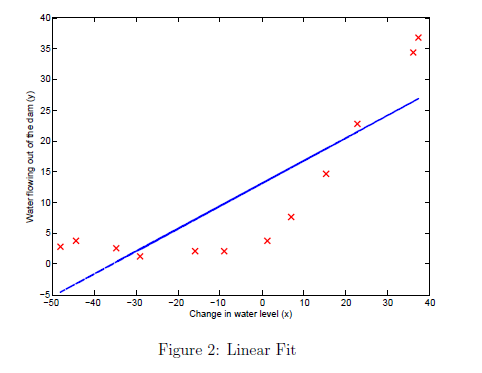

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

## 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

### 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\textrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

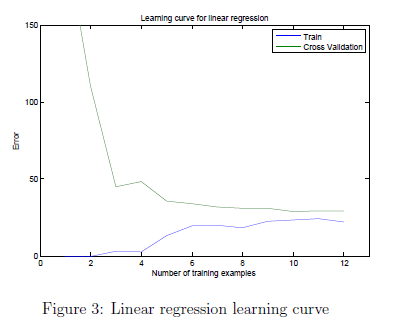

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

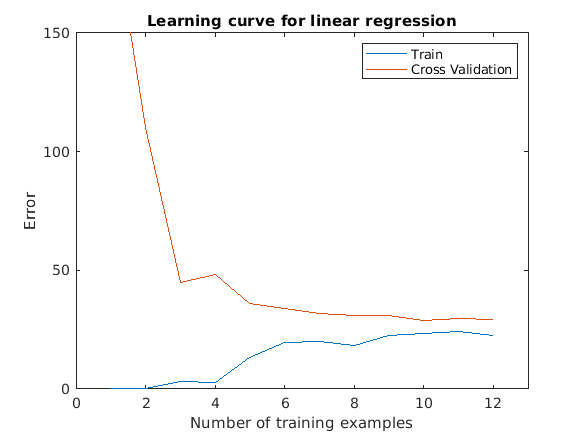

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')

xlabel('Number of training examples')
ylabel('Error')

# Training Examples	Train Error	Cross Validation Error


axis([0 13 0 150])

fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

## 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% % Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  



lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

grad =   -11.2176
  -10.1019
   -1.7795
   -8.3594
    0.0332
   -6.6599
    1.2410
   -5.3929
    1.9800


grad =   -11.1881
  -10.0333
   -1.8215
   -8.2855
   -0.0193
   -6.5871
    1.1835
   -5.3229
    1.9202


grad =   -11.1292
   -9.8962
   -1.9055
   -8.1378
   -0.1242
   -6.4417
    1.0684
   -5.1828
    1.8007


grad =   -10.9525
   -9.4847
   -2.1574
   -7.6947
   -0.4389
   -6.0053
    0.7232
   -4.7627
    1.4422


grad =   -10.4223
   -8.2502
   -2.9133
   -6.3652
   -1.3830
   -4.6960
   -0.3124
   -3.5022
    0.3667


grad =    -8.8317
   -4.5468
   -5.1811
   -2.3767
   -4.2154
   -0.7684
   -3.4192
    0.2791
   -2.8598


Iteration     1 | Cost: 8.273077e+01


grad =    -4.6160
   -4.6419
   -0.3218
   -3.7678
    0.5479
   -3.0907
    1.0543
   -2.6186
    1.3484


Iteration     2 | Cost: 2.687496e+01


grad =     0.6008
    8.1577
   -8.5599
   10.1042
   -9.6223
   10.6431
  -10.0327
   10.6563
  -10.1260


grad =    -2.8599
   -0.3333
   -3.0949
    0.9017
   -2.8755
    1.5323
   -2.6778
    1.8500
   -2.5141


Iteration     3 | Cost: 1.327780e+01


grad =     0.8911
    0.0898
    0.6080
    0.2747
    0.6809
    0.1232
    0.6088
   -0.0550
    0.5412


Iteration     4 | Cost: 3.455324e+00


grad =    -9.2367
    8.3804
  -20.4996
   13.1362
  -21.1557
   15.8659
  -20.7317
   17.2767
  -20.1015


grad =    -0.1217
    0.9189
   -1.5027
    1.5608
   -1.5027
    1.6975
   -1.5253
    1.6782
   -1.5231


grad =     0.4555
    0.4464
   -0.2998
    0.8279
   -0.2583
    0.8003
   -0.3091
    0.6905
   -0.3467


Iteration     5 | Cost: 2.870493e+00


grad =    -0.1865
   -0.4419
   -0.0792
   -0.0702
    0.1174
   -0.0275
    0.1612
   -0.0643
    0.1756


Iteration     6 | Cost: 2.404364e+00


grad =    -2.3873
    0.2336
   -3.1840
    1.0491
   -2.9038
    1.5308
   -2.6488
    1.7892
   -2.4498


grad =    -0.4066
   -0.3744
   -0.3897
    0.0417
   -0.1847
    0.1284
   -0.1198
    0.1210
   -0.0869


Iteration     7 | Cost: 2.372779e+00


grad =    -0.3800
   -0.4010
   -0.3161
   -0.0171
   -0.1036
    0.0560
   -0.0364
    0.0432
   -0.0036


grad =    -0.3268
   -0.4544
   -0.1689
   -0.1348
    0.0586
   -0.0886
    0.1304
   -0.1126
    0.1631


grad =    -0.1673
   -0.6143
    0.2728
   -0.4880
    0.5454
   -0.5225
    0.6308
   -0.5798
    0.6631


Iteration     8 | Cost: 1.771555e+00


grad =     0.0935
    0.2306
   -0.2668
    0.3191
   -0.0914
    0.2570
   -0.0409
    0.1733
   -0.0187


Iteration     9 | Cost: 1.210317e+00


grad =     0.5978
    0.2096
    0.3922
   -0.1400
    0.5874
   -0.3447
    0.6415
   -0.4717
    0.6547


grad =     0.3564
    0.2196
    0.0767
    0.0797
    0.2625
   -0.0567
    0.3149
   -0.1630
    0.3324


Iteration    10 | Cost: 9.412259e-01


grad =     0.2819
    0.6102
   -0.4305
    0.4375
   -0.3148
    0.3574
   -0.2692
    0.3026
   -0.2446


grad =     0.3072
    0.4777
   -0.2584
    0.3162
   -0.1189
    0.2169
   -0.0711
    0.1446
   -0.0489


Iteration    11 | Cost: 7.605932e-01


grad =     0.0754
   -0.0590
    0.0961
   -0.3130
    0.2850
   -0.3894
    0.3599
   -0.4183
    0.3926


grad =     0.1622
    0.1419
   -0.0367
   -0.0775
    0.1338
   -0.1624
    0.1986
   -0.2075
    0.2273


Iteration    12 | Cost: 6.473368e-01


grad =    -0.1437
    0.2538
   -0.4293
    0.1419
   -0.3233
    0.1506
   -0.2748
    0.1669
   -0.2469


grad =    -0.0045
    0.2029
   -0.2506
    0.0421
   -0.1153
    0.0082
   -0.0593
   -0.0035
   -0.0311


Iteration    13 | Cost: 5.858110e-01


grad =    -0.1683
   -0.1500
    0.0353
   -0.3133
    0.1618
   -0.3189
    0.2054
   -0.3013
    0.2220


grad =    -0.0983
    0.0007
   -0.0868
   -0.1615
    0.0435
   -0.1793
    0.0924
   -0.1741
    0.1140


Iteration    14 | Cost: 5.504289e-01


grad =    -0.1374
    0.0661
   -0.1521
   -0.0437
   -0.0788
   -0.0295
   -0.0606
   -0.0066
   -0.0550


Iteration    15 | Cost: 5.080652e-01


grad =    -0.0180
   -0.0466
    0.0994
   -0.1735
    0.1460
   -0.1698
    0.1380
   -0.1514
    0.1238


Iteration    16 | Cost: 4.816440e-01


grad =     0.2351
    0.1946
    0.0893
    0.1365
    0.0126
    0.1582
   -0.0709
    0.1773
   -0.1282


grad =     0.0448
    0.0133
    0.0969
   -0.0966
    0.1129
   -0.0884
    0.0862
   -0.0698
    0.0613


Iteration    17 | Cost: 4.728550e-01


grad =     0.0101
    0.0985
   -0.0378
    0.0109
   -0.0261
    0.0298
   -0.0501
    0.0525
   -0.0708


Iteration    18 | Cost: 4.667514e-01


grad =    -0.1648
    0.0426
   -0.2073
   -0.0151
   -0.1553
    0.0279
   -0.1468
    0.0667
   -0.1454


grad =    -0.0255
    0.0871
   -0.0723
    0.0056
   -0.0524
    0.0294
   -0.0698
    0.0554
   -0.0860


Iteration    19 | Cost: 4.649622e-01


grad =    -0.0257
    0.0561
   -0.0398
   -0.0311
   -0.0154
   -0.0096
   -0.0312
    0.0159
   -0.0472


Iteration    20 | Cost: 4.622788e-01


grad =    -0.0129
    0.0366
   -0.0061
   -0.0552
    0.0191
   -0.0367
    0.0023
   -0.0128
   -0.0148


grad =     0.0049
    0.0097
    0.0405
   -0.0886
    0.0668
   -0.0742
    0.0488
   -0.0524
    0.0301


Iteration    21 | Cost: 4.580159e-01


grad =     0.0273
    0.0540
    0.0121
   -0.0339
    0.0279
   -0.0180
    0.0043
    0.0028
   -0.0170


grad =     0.0511
    0.1009
   -0.0180
    0.0240
   -0.0133
    0.0416
   -0.0429
    0.0613
   -0.0670


Iteration    22 | Cost: 4.492319e-01


grad =     0.0857
    0.0641
    0.0481
   -0.0056
    0.0455
    0.0106
    0.0086
    0.0280
   -0.0207


Iteration    23 | Cost: 4.362053e-01


grad =     0.0175
    0.0102
    0.0365
   -0.0477
    0.0429
   -0.0222
    0.0125
    0.0018
   -0.0126


Iteration    24 | Cost: 4.232858e-01


grad =    -0.0313
    0.2088
   -0.2293
    0.2001
   -0.2420
    0.2453
   -0.2733
    0.2752
   -0.2940


grad =     0.0087
    0.0460
   -0.0115
   -0.0030
   -0.0085
    0.0261
   -0.0390
    0.0511
   -0.0634


Iteration    25 | Cost: 4.217012e-01


grad =    -0.0030
    0.0401
   -0.0164
   -0.0085
   -0.0101
    0.0209
   -0.0383
    0.0462
   -0.0611


grad =    -0.0263
    0.0281
   -0.0263
   -0.0193
   -0.0132
    0.0106
   -0.0367
    0.0363
   -0.0565


grad =    -0.0963
   -0.0078
   -0.0559
   -0.0520
   -0.0227
   -0.0202
   -0.0320
    0.0067
   -0.0428


Iteration    26 | Cost: 4.068726e-01


grad =    -0.0387
   -0.0588
    0.0452
   -0.1303
    0.0984
   -0.1205
    0.0969
   -0.1076
    0.0891


Iteration    27 | Cost: 3.910880e-01


grad = 9×1
    0.0271
    0.0556
   -0.0281
   -0.0085
    0.0190
   -0.0078
    0.0161
   -0.0055
    0.0090


Iteration    28 | Cost: 3.743045e-01


grad = 9×1
   -0.0468
    0.0355
   -0.0962
    0.0243
   -0.0639
    0.0513
   -0.0721
    0.0670
   -0.0801


Iteration    29 | Cost: 3.590625e-01


grad = 9×1
   -0.0928
   -0.1895
    0.0939
   -0.1947
    0.1365
   -0.1624
    0.1285
   -0.1408
    0.1178


grad = 9×1
   -0.0647
   -0.0520
   -0.0222
   -0.0609
    0.0141
   -0.0318
    0.0059
   -0.0139
   -0.0031


Iteration    30 | Cost: 3.535145e-01


grad = 9×1
   -0.0295
   -0.0428
    0.0065
   -0.0427
    0.0302
   -0.0152
    0.0133
   -0.0004
   -0.0011


Iteration    31 | Cost: 3.452417e-01


grad = 9×1
    0.0235
    0.1935
   -0.1967
    0.2135
   -0.1974
    0.2425
   -0.2218
    0.2522
   -0.2368


grad = 9×1
   -0.0224
   -0.0109
   -0.0210
   -0.0081
   -0.0006
    0.0197
   -0.0185
    0.0338
   -0.0330


Iteration    32 | Cost: 3.444915e-01


grad = 9×1
   -0.0092
   -0.0091
   -0.0088
   -0.0122
    0.0129
    0.0118
   -0.0047
    0.0236
   -0.0192


grad = 9×1
    0.0152
   -0.0057
    0.0136
   -0.0198
    0.0380
   -0.0029
    0.0209
    0.0047
    0.0063


Iteration    33 | Cost: 3.423546e-01


grad = 9×1
    0.0418
    0.0875
   -0.0605
    0.0728
   -0.0402
    0.0854
   -0.0567
    0.0883
   -0.0696


grad = 9×1
    0.0246
    0.0272
   -0.0126
    0.0129
    0.0104
    0.0283
   -0.0065
    0.0342
   -0.0205


Iteration    34 | Cost: 3.416004e-01


grad = 9×1
    0.0251
    0.0262
   -0.0109
    0.0069
    0.0159
    0.0198
    0.0014
    0.0244
   -0.0111


grad = 9×1
    0.0263
    0.0243
   -0.0076
   -0.0051
    0.0268
    0.0027
    0.0173
    0.0048
    0.0076


Iteration    35 | Cost: 3.384836e-01


grad = 9×1
   -0.0156
    0.0207
   -0.0473
    0.0014
   -0.0112
    0.0169
   -0.0173
    0.0239
   -0.0240


Iteration    36 | Cost: 3.360078e-01


grad = 9×1
   -0.0467
   -0.0620
    0.0118
   -0.0886
    0.0588
   -0.0728
    0.0577
   -0.0634
    0.0531


grad = 9×1
   -0.0295
   -0.0164
   -0.0208
   -0.0390
    0.0202
   -0.0233
    0.0164
   -0.0152
    0.0105


Iteration    37 | Cost: 3.349938e-01


grad = 9×1
   -0.0337
   -0.0219
   -0.0183
   -0.0429
    0.0218
   -0.0262
    0.0176
   -0.0174
    0.0117


grad = 9×1
   -0.0419
   -0.0328
   -0.0131
   -0.0508
    0.0249
   -0.0319
    0.0201
   -0.0218
    0.0140


grad = 9×1
   -0.0666
   -0.0657
    0.0022
   -0.0744
    0.0345
   -0.0492
    0.0275
   -0.0349
    0.0208


grad = 9×1
   -0.1181
   -0.1341
    0.0342
   -0.1234
    0.0543
   -0.0850
    0.0431
   -0.0623
    0.0350


Iteration    38 | Cost: 3.132232e-01


grad = 9×1
   -0.1080
    0.0481
   -0.1489
    0.1175
   -0.1820
    0.1783
   -0.2135
    0.2075
   -0.2276


grad = 9×1
   -0.1131
   -0.0450
   -0.0554
   -0.0056
   -0.0613
    0.0437
   -0.0824
    0.0697
   -0.0934


Iteration    39 | Cost: 3.025774e-01


grad = 9×1
   -0.0534
   -0.0387
   -0.0030
   -0.0053
   -0.0209
    0.0365
   -0.0493
    0.0568
   -0.0644


grad = 9×1
    0.0246
   -0.0304
    0.0654
   -0.0049
    0.0318
    0.0271
   -0.0061
    0.0399
   -0.0267


Iteration    40 | Cost: 2.780335e-01


grad = 9×1
    0.0407
    0.0095
    0.0124
    0.0034
    0.0055
    0.0159
   -0.0079
    0.0162
   -0.0107


Iteration    41 | Cost: 2.458465e-01


grad = 9×1
   -0.7643
   -0.7329
    0.4759
   -0.8360
    0.6192
   -0.8347
    0.6820
   -0.8182
    0.7147


grad = 9×1
   -0.0398
   -0.0647
    0.0587
   -0.0805
    0.0668
   -0.0692
    0.0611
   -0.0672
    0.0618


grad = 9×1
    0.0135
   -0.0155
    0.0280
   -0.0249
    0.0262
   -0.0128
    0.0154
   -0.0119
    0.0137


Iteration    42 | Cost: 2.450185e-01


grad = 9×1
   -0.0179
    0.0076
   -0.0112
    0.0046
   -0.0139
    0.0199
   -0.0235
    0.0222
   -0.0238


grad = 9×1
   -0.0052
   -0.0018
    0.0047
   -0.0074
    0.0023
    0.0066
   -0.0078
    0.0084
   -0.0086


Iteration    43 | Cost: 2.445260e-01


grad = 9×1
   -0.0144
   -0.0076
    0.0066
   -0.0192
    0.0112
   -0.0085
    0.0053
   -0.0084
    0.0068


Iteration    44 | Cost: 2.439497e-01


grad = 9×1
   -0.0099
    0.0284
   -0.0317
    0.0189
   -0.0271
    0.0291
   -0.0316
    0.0279
   -0.0286


grad = 9×1
   -0.0124
    0.0083
   -0.0103
   -0.0024
   -0.0057
    0.0081
   -0.0110
    0.0077
   -0.0088


Iteration    45 | Cost: 2.437323e-01


grad = 9×1
   -0.0015
    0.0118
   -0.0101
   -0.0024
   -0.0028
    0.0056
   -0.0064
    0.0034
   -0.0033


Iteration    46 | Cost: 2.434550e-01


grad = 9×1
   -0.0016
   -0.0216
    0.0262
   -0.0403
    0.0364
   -0.0339
    0.0331
   -0.0360
    0.0358


grad = 9×1
   -0.0016
    0.0044
   -0.0021
   -0.0108
    0.0059
   -0.0031
    0.0023
   -0.0053
    0.0053


Iteration    47 | Cost: 2.434070e-01


grad = 9×1
   -0.0010
    0.0044
   -0.0020
   -0.0099
    0.0053
   -0.0019
    0.0013
   -0.0039
    0.0041


grad = 9×1
    0.0002
    0.0044
   -0.0018
   -0.0083
    0.0041
    0.0005
   -0.0007
   -0.0011
    0.0016


grad = 9×1
    0.0038
    0.0043
   -0.0012
   -0.0033
    0.0006
    0.0077
   -0.0067
    0.0071
   -0.0058


Iteration    48 | Cost: 2.429084e-01


grad = 9×1
   -0.0025
   -0.0527
    0.0596
   -0.0652
    0.0651
   -0.0559
    0.0576
   -0.0563
    0.0575


grad = 9×1
    0.0028
   -0.0045
    0.0082
   -0.0129
    0.0106
   -0.0022
    0.0033
   -0.0027
    0.0040


Iteration    49 | Cost: 2.428414e-01


grad = 9×1
    0.0006
   -0.0067
    0.0100
   -0.0142
    0.0120
   -0.0032
    0.0044
   -0.0036
    0.0049


grad = 9×1
   -0.0038
   -0.0109
    0.0134
   -0.0168
    0.0147
   -0.0051
    0.0065
   -0.0052
    0.0067


grad = 9×1
   -0.0131
   -0.0199
    0.0207
   -0.0223
    0.0204
   -0.0093
    0.0110
   -0.0088
    0.0105


Iteration    50 | Cost: 2.423574e-01


grad = 9×1
   -0.0177
    0.0030
   -0.0062
    0.0099
   -0.0121
    0.0262
   -0.0237
    0.0277
   -0.0250


grad = 9×1
   -0.0159
   -0.0059
    0.0042
   -0.0025
    0.0004
    0.0125
   -0.0103
    0.0136
   -0.0113


Iteration    51 | Cost: 2.420593e-01


grad = 9×1
   -0.0081
   -0.0057
    0.0047
   -0.0017
    0.0010
    0.0130
   -0.0097
    0.0137
   -0.0106


grad = 9×1
    0.0077
   -0.0053
    0.0057
   -0.0001
    0.0022
    0.0139
   -0.0084
    0.0137
   -0.0092


grad = 9×1
    0.0374
   -0.0047
    0.0077
    0.0029
    0.0044
    0.0156
   -0.0060
    0.0139
   -0.0065


Iteration    52 | Cost: 2.400422e-01


grad = 9×1
    0.0168
   -0.0456
    0.0443
   -0.0445
    0.0521
   -0.0376
    0.0477
   -0.0427
    0.0502


Iteration    53 | Cost: 2.385391e-01


grad = 9×1
   -0.0173
   -0.0301
    0.0148
   -0.0236
    0.0285
   -0.0192
    0.0294
   -0.0276
    0.0361


Iteration    54 | Cost: 2.367359e-01


grad = 9×1
    0.0068
    0.0480
   -0.0636
    0.0690
   -0.0643
    0.0805
   -0.0694
    0.0748
   -0.0650


grad = 9×1
   -0.0096
   -0.0051
   -0.0103
    0.0061
   -0.0012
    0.0128
   -0.0022
    0.0052
    0.0037


Iteration    55 | Cost: 2.360896e-01


grad = 9×1
    0.0303
   -0.0079
    0.0037
   -0.0012
    0.0107
    0.0049
    0.0078
   -0.0024
    0.0123


grad = 9×1
    0.0151
   -0.0068
   -0.0016
    0.0016
    0.0061
    0.0079
    0.0040
    0.0005
    0.0090


Iteration    56 | Cost: 2.356901e-01


grad = 9×1
    0.0126
    0.0038
   -0.0116
    0.0124
   -0.0066
    0.0201
   -0.0099
    0.0138
   -0.0054


grad = 9×1
    0.0100
    0.0146
   -0.0218
    0.0234
   -0.0195
    0.0325
   -0.0240
    0.0273
   -0.0200


Iteration    57 | Cost: 2.348845e-01


grad = 9×1
    0.0013
   -0.0054
    0.0028
   -0.0049
    0.0057
    0.0039
    0.0009
    0.0001
    0.0040


Iteration    58 | Cost: 2.341373e-01


grad = 9×1
   -0.0623
    0.1055
   -0.1081
    0.0966
   -0.1221
    0.1142
   -0.1317
    0.1190
   -0.1296


grad = 9×1
   -0.0051
    0.0057
   -0.0083
    0.0053
   -0.0070
    0.0149
   -0.0124
    0.0120
   -0.0093


grad = 9×1
   -0.0010
   -0.0014
   -0.0012
   -0.0012
    0.0011
    0.0079
   -0.0040
    0.0045
   -0.0008


Iteration    59 | Cost: 2.341079e-01


grad = 9×1
   -0.0015
   -0.0046
    0.0027
   -0.0060
    0.0057
    0.0026
    0.0009
   -0.0009
    0.0042


Iteration    60 | Cost: 2.340687e-01


grad = 9×1
   -0.0013
   -0.0013
   -0.0006
   -0.0029
    0.0023
    0.0057
   -0.0024
    0.0022
    0.0009


grad = 9×1
   -0.0008
    0.0051
   -0.0069
    0.0031
   -0.0043
    0.0117
   -0.0089
    0.0083
   -0.0054


Iteration    61 | Cost: 2.339816e-01


grad = 9×1
    0.0007
    0.0061
   -0.0062
    0.0002
   -0.0023
    0.0077
   -0.0059
    0.0040
   -0.0019


Iteration    62 | Cost: 2.338806e-01


grad = 9×1
   -0.0006
   -0.0147
    0.0156
   -0.0228
    0.0216
   -0.0162
    0.0183
   -0.0201
    0.0222


grad = 9×1
    0.0004
    0.0012
   -0.0012
   -0.0051
    0.0033
    0.0021
   -0.0003
   -0.0016
    0.0037


Iteration    63 | Cost: 2.338603e-01


grad = 9×1
   -0.0001
    0.0012
   -0.0014
   -0.0046
    0.0027
    0.0029
   -0.0010
   -0.0008
    0.0028


grad = 9×1
   -0.0011
    0.0011
   -0.0019
   -0.0035
    0.0016
    0.0045
   -0.0026
    0.0010
    0.0011


grad = 9×1
   -0.0041
    0.0008
   -0.0035
   -0.0003
   -0.0019
    0.0091
   -0.0071
    0.0063
   -0.0039


Iteration    64 | Cost: 2.336272e-01


grad = 9×1
   -0.0024
   -0.0243
    0.0241
   -0.0276
    0.0275
   -0.0193
    0.0224
   -0.0223
    0.0251


grad = 9×1
   -0.0036
   -0.0073
    0.0054
   -0.0091
    0.0076
   -0.0000
    0.0025
   -0.0030
    0.0054


Iteration    65 | Cost: 2.335684e-01


grad = 9×1
   -0.0012
   -0.0098
    0.0089
   -0.0111
    0.0107
   -0.0020
    0.0052
   -0.0050
    0.0080


grad = 9×1
    0.0036
   -0.0149
    0.0157
   -0.0150
    0.0170
   -0.0059
    0.0108
   -0.0091
    0.0130


Iteration    66 | Cost: 2.333511e-01


grad = 9×1
    0.0066
   -0.0050
    0.0056
   -0.0016
    0.0046
    0.0085
   -0.0025
    0.0055
   -0.0006


Iteration    67 | Cost: 2.331255e-01


grad = 9×1
   -0.0014
   -0.0040
    0.0009
   -0.0011
    0.0014
    0.0088
   -0.0046
    0.0057
   -0.0019


grad = 9×1
   -0.0174
   -0.0020
   -0.0084
   -0.0002
   -0.0049
    0.0094
   -0.0086
    0.0061
   -0.0045


Iteration    68 | Cost: 2.325848e-01


grad = 9×1
   -0.0158
   -0.0338
    0.0273
   -0.0453
    0.0409
   -0.0419
    0.0422
   -0.0477
    0.0486


grad = 9×1
   -0.0169
   -0.0119
    0.0027
   -0.0142
    0.0094
   -0.0066
    0.0072
   -0.0107
    0.0121


Iteration    69 | Cost: 2.324193e-01


grad = 9×1
   -0.0112
   -0.0067
   -0.0005
   -0.0106
    0.0071
   -0.0042
    0.0057
   -0.0090
    0.0111


grad = 9×1
    0.0001
    0.0038
   -0.0071
   -0.0034
    0.0025
    0.0007
    0.0026
   -0.0057
    0.0089


Iteration    70 | Cost: 2.318731e-01


grad = 9×1
    0.0007
    0.0400
   -0.0476
    0.0473
   -0.0495
    0.0581
   -0.0548
    0.0545
   -0.0508


grad = 9×1
    0.0002
    0.0123
   -0.0166
    0.0085
   -0.0097
    0.0142
   -0.0109
    0.0084
   -0.0051


Iteration    71 | Cost: 2.317566e-01


grad = 9×1
    0.0003
    0.0086
   -0.0126
    0.0059
   -0.0070
    0.0123
   -0.0090
    0.0071
   -0.0038


grad = 9×1
    0.0005
    0.0010
   -0.0047
    0.0006
   -0.0015
    0.0085
   -0.0053
    0.0044
   -0.0012


Iteration    72 | Cost: 2.312988e-01


grad = 9×1
   -0.0039
   -0.1037
    0.1198
   -0.1414
    0.1492
   -0.1503
    0.1564
   -0.1613
    0.1645


grad = 9×1
    0.0001
   -0.0094
    0.0077
   -0.0136
    0.0136
   -0.0074
    0.0109
   -0.0122
    0.0154


grad = 9×1
    0.0004
   -0.0013
   -0.0019
   -0.0026
    0.0019
    0.0050
   -0.0017
    0.0006
    0.0025


Iteration    73 | Cost: 2.312910e-01


grad = 9×1
    0.0003
   -0.0012
   -0.0017
   -0.0026
    0.0021
    0.0049
   -0.0015
    0.0006
    0.0027


grad = 9×1
    0.0000
   -0.0011
   -0.0014
   -0.0027
    0.0024
    0.0048
   -0.0012
    0.0004
    0.0029


grad = 9×1
   -0.0007
   -0.0007
   -0.0003
   -0.0028
    0.0034
    0.0044
   -0.0003
   -0.0002
    0.0038


grad = 9×1
   -0.0029
    0.0007
    0.0029
   -0.0031
    0.0063
    0.0032
    0.0024
   -0.0018
    0.0063


grad = 9×1
   -0.0095
    0.0046
    0.0126
   -0.0040
    0.0151
   -0.0002
    0.0105
   -0.0065
    0.0137


Iteration    74 | Cost: 2.303487e-01


grad = 9×1
   -0.0064
    0.0362
   -0.0268
    0.0336
   -0.0286
    0.0406
   -0.0342
    0.0358
   -0.0307


grad = 9×1
   -0.0078
    0.0220
   -0.0091
    0.0167
   -0.0089
    0.0223
   -0.0141
    0.0168
   -0.0107


Iteration    75 | Cost: 2.299984e-01


grad = 9×1
   -0.0021
    0.0265
   -0.0239
    0.0230
   -0.0242
    0.0308
   -0.0288
    0.0269
   -0.0247


Iteration    76 | Cost: 2.294918e-01


grad = 9×1
    0.0001
    0.0139
   -0.0138
    0.0082
   -0.0124
    0.0158
   -0.0162
    0.0123
   -0.0118


grad = 9×1
    0.0040
   -0.0079
    0.0035
   -0.0173
    0.0080
   -0.0102
    0.0057
   -0.0131
    0.0106


Iteration    77 | Cost: 2.285349e-01


grad = 9×1
    0.0188
   -0.0281
    0.0033
   -0.0405
    0.0093
   -0.0300
    0.0092
   -0.0289
    0.0155


Iteration    78 | Cost: 2.276456e-01


grad = 9×1
    0.0204
    0.0081
   -0.0359
    0.0005
   -0.0363
    0.0142
   -0.0383
    0.0170
   -0.0322


grad = 9×1
    0.0199
   -0.0042
   -0.0226
   -0.0134
   -0.0208
   -0.0008
   -0.0221
    0.0014
   -0.0160


Iteration    79 | Cost: 2.270134e-01


grad = 9×1
    0.0098
    0.0037
   -0.0102
   -0.0103
   -0.0110
   -0.0008
   -0.0143
   -0.0004
   -0.0095


grad = 9×1
   -0.0039
    0.0145
    0.0067
   -0.0061
    0.0023
   -0.0007
   -0.0037
   -0.0027
   -0.0008


Iteration    80 | Cost: 2.255225e-01


grad = 9×1
   -0.0045
    0.0029
    0.0105
   -0.0132
    0.0022
   -0.0043
   -0.0056
   -0.0036
   -0.0036


grad = 9×1
   -0.0056
   -0.0203
    0.0180
   -0.0275
    0.0019
   -0.0115
   -0.0094
   -0.0054
   -0.0094


Iteration    81 | Cost: 2.199186e-01


grad = 9×1
    0.0148
    0.1549
   -0.1066
    0.1663
   -0.1510
    0.1823
   -0.1742
    0.1837
   -0.1787


grad = 9×1
   -0.0015
    0.0155
   -0.0075
    0.0122
   -0.0294
    0.0282
   -0.0431
    0.0333
   -0.0440


Iteration    82 | Cost: 2.190030e-01


grad = 9×1
    0.0045
    0.0298
   -0.0022
    0.0233
   -0.0264
    0.0357
   -0.0416
    0.0383
   -0.0435


grad = 9×1
    0.0165
    0.0584
    0.0082
    0.0454
   -0.0205
    0.0508
   -0.0386
    0.0484
   -0.0423


Iteration    83 | Cost: 2.157581e-01


grad = 9×1
    0.0174
    0.0001
    0.0772
   -0.0278
    0.0578
   -0.0292
    0.0430
   -0.0339
    0.0400


Iteration    84 | Cost: 2.141665e-01


grad = 9×1
    0.0035
   -0.1166
    0.1662
   -0.1675
    0.1727
   -0.1782
    0.1723
   -0.1844
    0.1761


grad = 9×1
    0.0147
   -0.0230
    0.0948
   -0.0554
    0.0806
   -0.0587
    0.0686
   -0.0636
    0.0669


Iteration    85 | Cost: 2.136231e-01


grad = 9×1
    0.0139
   -0.0167
    0.0855
   -0.0474
    0.0706
   -0.0499
    0.0587
   -0.0546
    0.0572


grad = 9×1
    0.0124
   -0.0041
    0.0668
   -0.0314
    0.0508
   -0.0324
    0.0390
   -0.0365
    0.0380


grad = 9×1
    0.0079
    0.0336
    0.0109
    0.0165
   -0.0087
    0.0200
   -0.0201
    0.0178
   -0.0199


Iteration    86 | Cost: 2.083897e-01


grad = 9×1
   -0.0289
   -0.0623
   -0.0110
   -0.0724
   -0.0055
   -0.0581
    0.0009
   -0.0506
    0.0121


grad = 9×1
   -0.0111
   -0.0158
   -0.0004
   -0.0293
   -0.0070
   -0.0202
   -0.0093
   -0.0175
   -0.0034


Iteration    87 | Cost: 2.058742e-01


grad = 9×1
   -0.0239
    0.0191
   -0.0876
    0.0197
   -0.0886
    0.0340
   -0.0832
    0.0388
   -0.0712


grad = 9×1
   -0.0178
    0.0025
   -0.0461
   -0.0036
   -0.0497
    0.0082
   -0.0480
    0.0120
   -0.0389


Iteration    88 | Cost: 2.045546e-01


grad = 9×1
   -0.0186
   -0.0093
   -0.0384
   -0.0188
   -0.0361
   -0.0101
   -0.0308
   -0.0079
   -0.0198


grad = 9×1
   -0.0202
   -0.0329
   -0.0231
   -0.0492
   -0.0089
   -0.0465
    0.0035
   -0.0477
    0.0183


Iteration    89 | Cost: 2.005053e-01


grad = 9×1
   -0.0057
    0.0485
   -0.0686
    0.0344
   -0.0579
    0.0276
   -0.0459
    0.0176
   -0.0306


Iteration    90 | Cost: 1.980049e-01


grad = 9×1
    0.0346
    0.0588
    0.0462
    0.0124
    0.0691
   -0.0325
    0.0836
   -0.0682
    0.0981


grad = 9×1
    0.0013
    0.0503
   -0.0485
    0.0306
   -0.0357
    0.0171
   -0.0233
    0.0026
   -0.0081


Iteration    91 | Cost: 1.973128e-01


grad = 9×1
   -0.0002
    0.0265
   -0.0269
    0.0042
   -0.0121
   -0.0091
    0.0006
   -0.0228
    0.0156


Iteration    92 | Cost: 1.963551e-01


grad = 9×1
    0.0002
    0.0234
   -0.0217
    0.0039
   -0.0097
   -0.0082
    0.0011
   -0.0212
    0.0149


grad = 9×1
    0.0009
    0.0172
   -0.0113
    0.0031
   -0.0049
   -0.0063
    0.0020
   -0.0180
    0.0134


grad = 9×1
    0.0029
    0.0014
    0.0153
    0.0012
    0.0074
   -0.0017
    0.0044
   -0.0098
    0.0095


Iteration    93 | Cost: 1.907462e-01


grad = 9×1
   -0.0568
    0.4500
   -0.7624
    0.6472
   -0.8489
    0.7481
   -0.8683
    0.7899
   -0.8582


grad = 9×1
   -0.0031
    0.0462
   -0.0625
    0.0658
   -0.0782
    0.0733
   -0.0828
    0.0701
   -0.0772


grad = 9×1
    0.0021
    0.0074
    0.0049
    0.0098
   -0.0040
    0.0083
   -0.0072
    0.0008
   -0.0021


Iteration    94 | Cost: 1.906713e-01


grad = 9×1
    0.0003
    0.0010
    0.0035
    0.0046
   -0.0044
    0.0043
   -0.0070
   -0.0022
   -0.0014


grad = 9×1
   -0.0018
   -0.0067
    0.0019
   -0.0017
   -0.0050
   -0.0005
   -0.0067
   -0.0059
   -0.0006


Iteration    95 | Cost: 1.905061e-01


grad = 9×1
   -0.0019
   -0.0065
    0.0015
   -0.0016
   -0.0049
   -0.0005
   -0.0065
   -0.0060
   -0.0003


grad = 9×1
   -0.0021
   -0.0061
    0.0007
   -0.0015
   -0.0048
   -0.0006
   -0.0060
   -0.0063
    0.0001


grad = 9×1
   -0.0028
   -0.0048
   -0.0016
   -0.0010
   -0.0044
   -0.0010
   -0.0048
   -0.0071
    0.0015


grad = 9×1
   -0.0046
   -0.0010
   -0.0085
    0.0003
   -0.0032
   -0.0020
   -0.0011
   -0.0095
    0.0057


Iteration    96 | Cost: 1.839298e-01


grad = 9×1
    0.1280
    0.1921
   -0.0173
    0.2166
   -0.0760
    0.2110
   -0.1168
    0.1946
   -0.1359


grad = 9×1
    0.0086
    0.0183
   -0.0094
    0.0219
   -0.0105
    0.0193
   -0.0127
    0.0109
   -0.0084


Iteration    97 | Cost: 1.835354e-01


grad = 9×1
    0.0258
    0.0059
    0.0304
    0.0065
    0.0248
    0.0016
    0.0177
   -0.0080
    0.0181


grad = 9×1
    0.0154
    0.0134
    0.0063
    0.0158
    0.0034
    0.0123
   -0.0008
    0.0035
    0.0020


Iteration    98 | Cost: 1.833599e-01


grad = 9×1
    0.0092
    0.0004
    0.0110
    0.0026
    0.0102
   -0.0001
    0.0073
   -0.0081
    0.0107


Iteration    99 | Cost: 1.831295e-01


grad = 9×1
    0.0015
    0.0063
   -0.0073
    0.0127
   -0.0086
    0.0128
   -0.0111
    0.0064
   -0.0071


Iteration   100 | Cost: 1.830116e-01


grad = 9×1
   -0.0298
   -0.0230
   -0.0228
   -0.0105
   -0.0189
   -0.0034
   -0.0171
   -0.0044
   -0.0102


grad = 9×1
   -0.0023
    0.0028
   -0.0092
    0.0099
   -0.0099
    0.0108
   -0.0118
    0.0051
   -0.0075


Iteration   101 | Cost: 1.829906e-01


grad = 9×1
   -0.0021
    0.0001
   -0.0060
    0.0067
   -0.0063
    0.0073
   -0.0081
    0.0015
   -0.0038


grad = 9×1
   -0.0017
   -0.0044
   -0.0004
    0.0010
   -0.0002
    0.0012
   -0.0018
   -0.0047
    0.0025


Iteration   102 | Cost: 1.829334e-01


grad = 9×1
    0.0023
   -0.0003
    0.0019
    0.0039
    0.0014
    0.0032
   -0.0009
   -0.0034
    0.0030


grad = 9×1
    0.0066
    0.0040
    0.0045
    0.0071
    0.0031
    0.0053
    0.0001
   -0.0020
    0.0035


Iteration   103 | Cost: 1.828149e-01


grad = 9×1
    0.0064
    0.0026
    0.0060
    0.0049
    0.0047
    0.0032
    0.0016
   -0.0038
    0.0049


grad = 9×1
    0.0059
   -0.0002
    0.0090
    0.0004
    0.0078
   -0.0011
    0.0046
   -0.0076
    0.0077


grad = 9×1
    0.0047
   -0.0087
    0.0180
   -0.0129
    0.0171
   -0.0139
    0.0137
   -0.0189
    0.0162


Iteration   104 | Cost: 1.814075e-01


grad = 9×1
   -0.0007
    0.0440
   -0.0453
    0.0487
   -0.0543
    0.0540
   -0.0605
    0.0524
   -0.0586


grad = 9×1
    0.0030
    0.0081
   -0.0022
    0.0067
   -0.0056
    0.0078
   -0.0100
    0.0038
   -0.0076


Iteration   105 | Cost: 1.810678e-01


grad = 9×1
   -0.0087
    0.0116
   -0.0178
    0.0099
   -0.0222
    0.0148
   -0.0267
    0.0143
   -0.0245


grad = 9×1
   -0.0031
    0.0099
   -0.0103
    0.0084
   -0.0143
    0.0114
   -0.0187
    0.0093
   -0.0165


Iteration   106 | Cost: 1.808903e-01


grad = 9×1
   -0.0053
   -0.0050
    0.0044
   -0.0102
    0.0024
   -0.0077
   -0.0015
   -0.0094
    0.0008


Iteration   107 | Cost: 1.807608e-01


grad = 9×1
   -0.0028
   -0.0077
    0.0185
   -0.0212
    0.0163
   -0.0199
    0.0112
   -0.0209
    0.0119


grad = 9×1
   -0.0046
   -0.0058
    0.0086
   -0.0135
    0.0066
   -0.0114
    0.0023
   -0.0129
    0.0041


Iteration   108 | Cost: 1.807074e-01


grad = 9×1
   -0.0037
    0.0010
    0.0025
   -0.0058
   -0.0005
   -0.0034
   -0.0051
   -0.0049
   -0.0035


Iteration   109 | Cost: 1.806379e-01


grad = 9×1
   -0.0006
    0.0037
    0.0030
   -0.0032
   -0.0004
   -0.0013
   -0.0053
   -0.0033
   -0.0038


grad = 9×1
    0.0056
    0.0092
    0.0039
    0.0020
   -0.0001
    0.0028
   -0.0056
   -0.0002
   -0.0045


Iteration   110 | Cost: 1.804366e-01


grad = 9×1
    0.0039
   -0.0073
    0.0190
   -0.0165
    0.0179
   -0.0167
    0.0135
   -0.0201
    0.0150


Iteration   111 | Cost: 1.803563e-01


grad = 9×1
   -0.0042
   -0.0363
    0.0374
   -0.0452
    0.0424
   -0.0463
    0.0409
   -0.0501
    0.0437


grad = 9×1
    0.0023
   -0.0132
    0.0228
   -0.0223
    0.0229
   -0.0227
    0.0191
   -0.0262
    0.0209


Iteration   112 | Cost: 1.803236e-01


grad = 9×1
    0.0021
   -0.0119
    0.0210
   -0.0206
    0.0210
   -0.0209
    0.0172
   -0.0243
    0.0190


grad = 9×1
    0.0017
   -0.0093
    0.0175
   -0.0171
    0.0172
   -0.0171
    0.0133
   -0.0205
    0.0152


grad = 9×1
    0.0006
   -0.0013
    0.0071
   -0.0067
    0.0058
   -0.0059
    0.0018
   -0.0091
    0.0037


Iteration   113 | Cost: 1.799170e-01


grad = 9×1
    0.0207
    0.1835
   -0.1609
    0.2015
   -0.1938
    0.2132
   -0.2103
    0.2133
   -0.2126


grad = 9×1
    0.0026
    0.0172
   -0.0097
    0.0141
   -0.0141
    0.0160
   -0.0194
    0.0132
   -0.0179


grad = 9×1
    0.0008
    0.0006
    0.0054
   -0.0046
    0.0038
   -0.0037
   -0.0003
   -0.0069
    0.0016


grad = 9×1
    0.0007
   -0.0010
    0.0068
   -0.0064
    0.0055
   -0.0056
    0.0015
   -0.0087
    0.0034


Iteration   114 | Cost: 1.799170e-01


grad = 9×1
    0.0007
   -0.0010
    0.0068
   -0.0064
    0.0055
   -0.0056
    0.0015
   -0.0087
    0.0034


grad = 9×1
    0.0007
   -0.0010
    0.0068
   -0.0064
    0.0055
   -0.0055
    0.0014
   -0.0087
    0.0034


grad = 9×1
    0.0007
   -0.0009
    0.0067
   -0.0063
    0.0054
   -0.0054
    0.0013
   -0.0086
    0.0033


grad = 9×1
    0.0007
   -0.0007
    0.0064
   -0.0060
    0.0051
   -0.0051
    0.0010
   -0.0083
    0.0029


grad = 9×1
    0.0006
    0.0000
    0.0056
   -0.0051
    0.0042
   -0.0042
    0.0001
   -0.0074
    0.0020


grad = 9×1
    0.0006
    0.0021
    0.0033
   -0.0026
    0.0016
   -0.0015
   -0.0026
   -0.0046
   -0.0007


Iteration   115 | Cost: 1.798949e-01


grad = 9×1
    0.0002
    0.0033
    0.0015
   -0.0009
   -0.0003
    0.0003
   -0.0045
   -0.0027
   -0.0026


grad = 9×1
   -0.0005
    0.0056
   -0.0019
    0.0023
   -0.0040
    0.0039
   -0.0083
    0.0010
   -0.0063


grad = 9×1
   -0.0019
    0.0103
   -0.0088
    0.0089
   -0.0115
    0.0112
   -0.0159
    0.0084
   -0.0138


Iteration   116 | Cost: 1.797826e-01


grad = 9×1
   -0.0035
    0.0052
   -0.0054
    0.0040
   -0.0071
    0.0062
   -0.0112
    0.0034
   -0.0091


grad = 9×1
   -0.0067
   -0.0049
    0.0015
   -0.0058
    0.0015
   -0.0037
   -0.0019
   -0.0065
    0.0005


Iteration   117 | Cost: 1.793168e-01


grad = 9×1
    0.0025
    0.0152
   -0.0138
    0.0190
   -0.0161
    0.0210
   -0.0207
    0.0170
   -0.0189


Iteration   118 | Cost: 1.790947e-01


grad = 9×1
    0.0697
    0.0831
   -0.0395
    0.1051
   -0.0469
    0.1000
   -0.0571
    0.0857
   -0.0585


grad = 9×1
    0.0092
    0.0220
   -0.0164
    0.0276
   -0.0192
    0.0289
   -0.0243
    0.0239
   -0.0228


grad = 9×1
    0.0044
    0.0172
   -0.0146
    0.0215
   -0.0170
    0.0233
   -0.0218
    0.0190
   -0.0200


Iteration   119 | Cost: 1.790849e-01


grad = 9×1
    0.0044
    0.0166
   -0.0139
    0.0208
   -0.0162
    0.0225
   -0.0210
    0.0182
   -0.0192


grad = 9×1
    0.0045
    0.0154
   -0.0126
    0.0194
   -0.0148
    0.0211
   -0.0195
    0.0167
   -0.0177


grad = 9×1
    0.0046
    0.0119
   -0.0088
    0.0152
   -0.0104
    0.0166
   -0.0149
    0.0121
   -0.0131


grad = 9×1
    0.0049
    0.0014
    0.0029
    0.0026
    0.0029
    0.0031
   -0.0012
   -0.0016
    0.0006


Iteration   120 | Cost: 1.788040e-01


grad = 9×1
   -0.0359
   -0.0204
   -0.0149
   -0.0143
   -0.0095
   -0.0083
   -0.0091
   -0.0088
   -0.0044


grad = 9×1
   -0.0019
   -0.0023
   -0.0001
   -0.0002
    0.0008
    0.0012
   -0.0025
   -0.0028
   -0.0002


Iteration   121 | Cost: 1.787596e-01


grad = 9×1
   -0.0020
    0.0019
   -0.0044
    0.0040
   -0.0035
    0.0053
   -0.0067
    0.0012
   -0.0042


grad = 9×1
   -0.0021
    0.0104
   -0.0130
    0.0124
   -0.0121
    0.0136
   -0.0149
    0.0092
   -0.0121


Iteration   122 | Cost: 1.786264e-01


grad = 9×1
   -0.0018
    0.0100
   -0.0112
    0.0092
   -0.0084
    0.0091
   -0.0103
    0.0041
   -0.0070


grad = 9×1
   -0.0012
    0.0092
   -0.0077
    0.0027
   -0.0012
    0.0000
   -0.0011
   -0.0061
    0.0032


Iteration   123 | Cost: 1.781722e-01


grad = 9×1
    0.0036
   -0.0244
    0.0214
   -0.0301
    0.0278
   -0.0308
    0.0268
   -0.0350
    0.0298


grad = 9×1
    0.0011
   -0.0072
    0.0065
   -0.0133
    0.0129
   -0.0150
    0.0125
   -0.0202
    0.0161


Iteration   124 | Cost: 1.779780e-01


grad = 9×1
    0.0033
   -0.0068
    0.0026
   -0.0088
    0.0063
   -0.0081
    0.0044
   -0.0119
    0.0072


grad = 9×1
    0.0055
   -0.0064
   -0.0015
   -0.0040
   -0.0007
   -0.0008
   -0.0042
   -0.0033
   -0.0022


Iteration   125 | Cost: 1.775786e-01


grad = 9×1
   -0.0282
    0.0460
   -0.0030
    0.0448
   -0.0111
    0.0413
   -0.0206
    0.0332
   -0.0222


grad = 9×1
   -0.0001
    0.0023
   -0.0017
    0.0041
   -0.0024
    0.0062
   -0.0069
    0.0028
   -0.0055


Iteration   126 | Cost: 1.775123e-01


grad = 9×1
   -0.0056
   -0.0062
    0.0166
   -0.0087
    0.0172
   -0.0092
    0.0125
   -0.0139
    0.0136


grad = 9×1
   -0.0017
   -0.0002
    0.0036
    0.0004
    0.0033
    0.0017
   -0.0012
   -0.0021
    0.0001


Iteration   127 | Cost: 1.774930e-01


grad = 9×1
   -0.0015
   -0.0003
    0.0031
    0.0000
    0.0032
    0.0012
   -0.0011
   -0.0026
    0.0004


grad = 9×1
   -0.0010
   -0.0004
    0.0020
   -0.0007
    0.0030
    0.0003
   -0.0007
   -0.0037
    0.0011


grad = 9×1
    0.0004
   -0.0008
   -0.0011
   -0.0028
    0.0025
   -0.0026
    0.0004
   -0.0069
    0.0032


Iteration   128 | Cost: 1.772584e-01


grad = 9×1
    0.0005
    0.0402
   -0.0426
    0.0452
   -0.0441
    0.0475
   -0.0478
    0.0433
   -0.0452


grad = 9×1
    0.0004
    0.0041
   -0.0061
    0.0030
   -0.0031
    0.0034
   -0.0053
   -0.0009
   -0.0025


Iteration   129 | Cost: 1.772375e-01


grad = 9×1
    0.0003
    0.0063
   -0.0073
    0.0054
   -0.0046
    0.0058
   -0.0071
    0.0014
   -0.0044


grad = 9×1
    0.0001
    0.0106
   -0.0096
    0.0101
   -0.0077
    0.0105
   -0.0105
    0.0059
   -0.0081


grad = 9×1
   -0.0003
    0.0182
   -0.0136
    0.0185
   -0.0130
    0.0187
   -0.0166
    0.0138
   -0.0145


Iteration   130 | Cost: 1.771016e-01


grad = 9×1
   -0.0007
    0.0185
   -0.0084
    0.0180
   -0.0082
    0.0173
   -0.0124
    0.0118
   -0.0108


grad = 9×1
   -0.0017
    0.0189
    0.0019
    0.0168
    0.0013
    0.0145
   -0.0040
    0.0078
   -0.0033


    After learning the parameters $\theta$, the code below will generate two plots (Figures 4,5) for polynomial regression with $\lambda = 0$. 

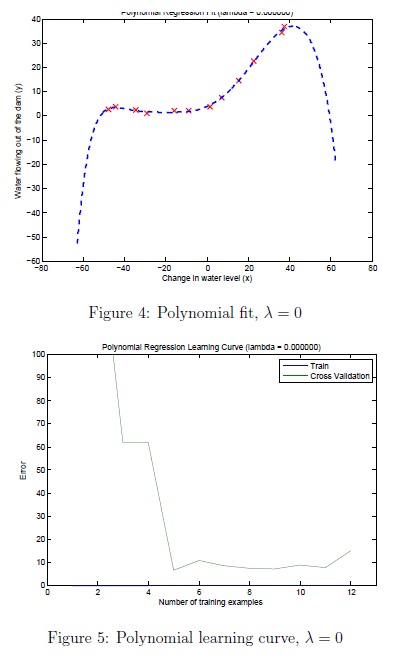

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

### 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

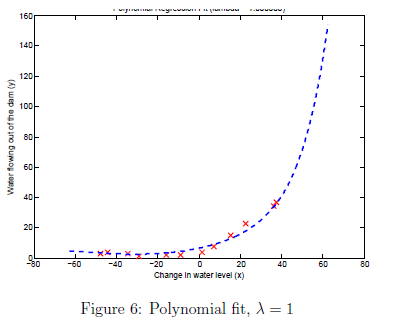

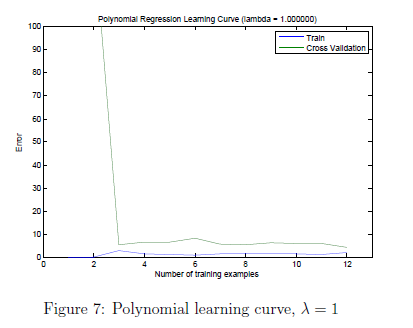

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

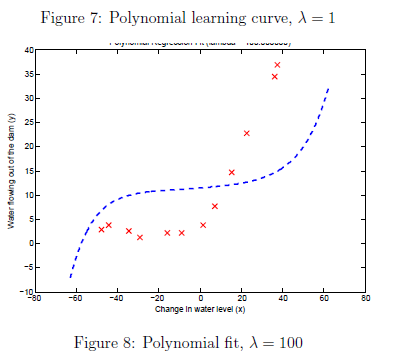

### 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');
for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

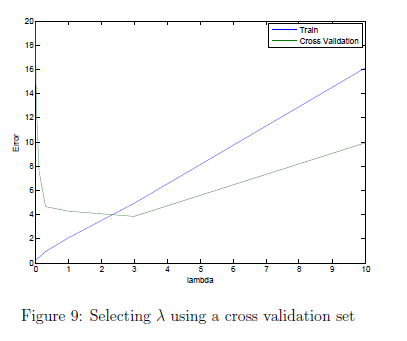

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%



### 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

lambda = 0.01;
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

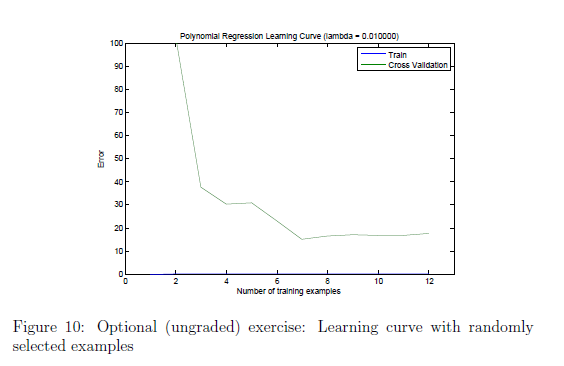

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

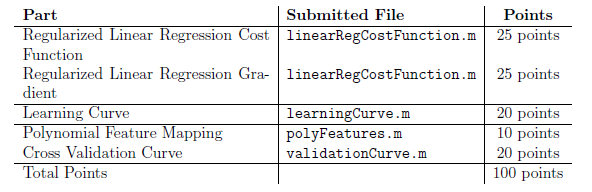

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

.                        ex5_companion.mlx        fmincg.m                 linearRegCostFunction.m  submit.m                 validationCurve.m        
..                       ex5data1.mat             learningCurve.m          plotFit.m                token.mat                
ex5.mlx                  featureNormalize.m       lib                      polyFeatures.m           trainLinearReg.m         

